Text

S_1 = 99;% Susceptible people
I_1 = 1; % Infected people
R_1 = 0; % Recovered people

i = 0.9; % Infectivity rate is 90% according to the CDC
r = 0.0714; % The average person takes two weeks to recover

m = 1; % Mask effectiveness (1 is worst, 0 is best)

t_end = 40; % Time simulation end, in weeks

Text

% Normal Model
% S(t+1) = S(t) - (I(t) * S(t) * i)
% I(t+1) = I(t) + (I(t) * S(t) * i) - (I(t) * r)
% R(t+1) = R(t) + (I(t) * r)

% Mask Model
% S(t+1) = S(t) - (I(t) * S(t) * i * m)
% I(t+1) = I(t) + (I(t) * S(t) * i * m) - (I(t) * r)
% R(t+1) = R(t) + (I(t) * r)

Text

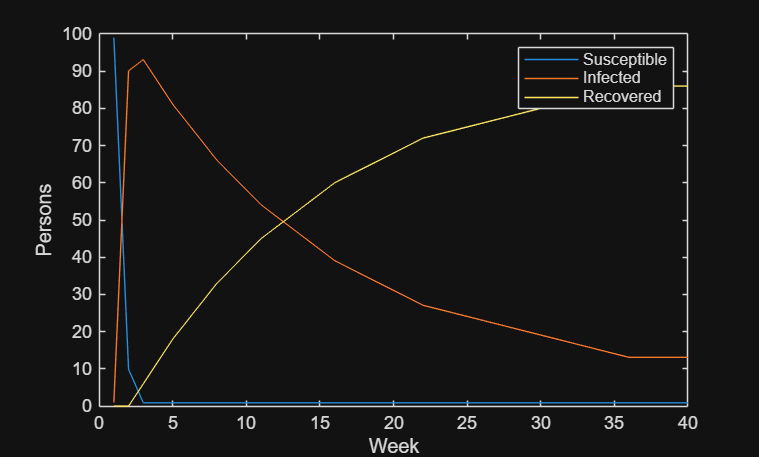

[S, I, R, W] = simulate_sir(S_1, I_1, R_1, m, i, r, t_end);

% Plot - baseline
figure()
plot(W, S, 'DisplayName', 'Susceptible'); hold on
plot(W, I, 'DisplayName', 'Infected')
plot(W, R, 'DisplayName', 'Recovered')

xlabel("Week")
ylabel("Persons")
legend()

Text

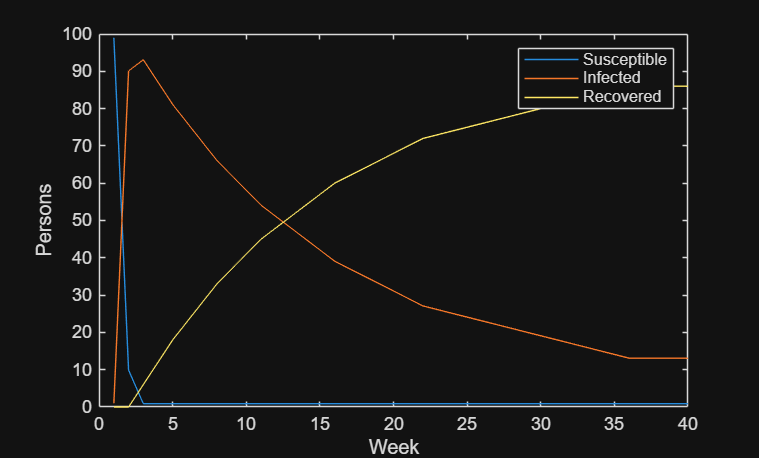

mi = 1

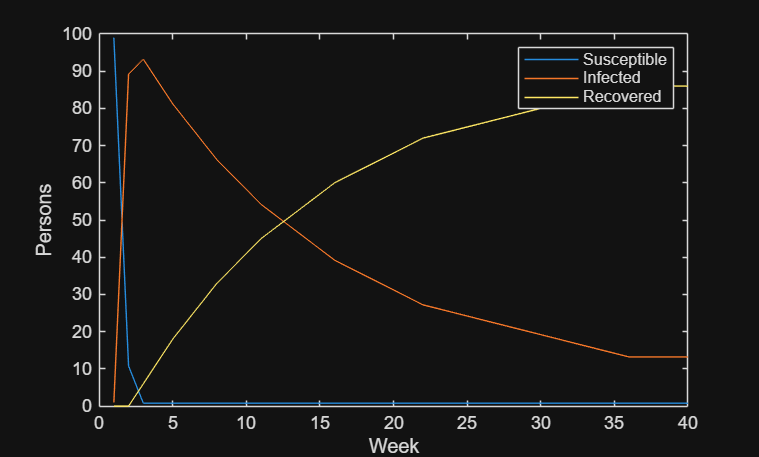

mi = 0.9900

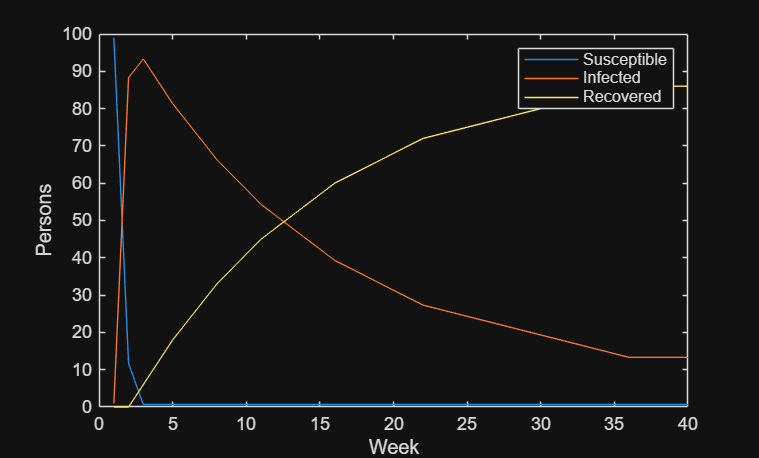

mi = 0.9800

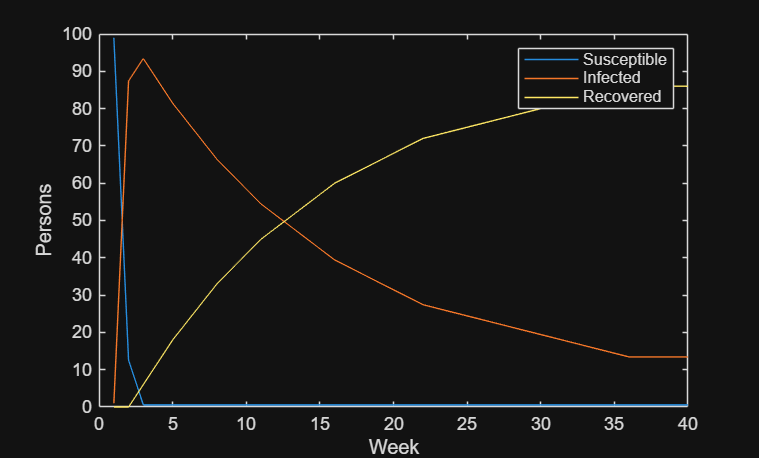

mi = 0.9700

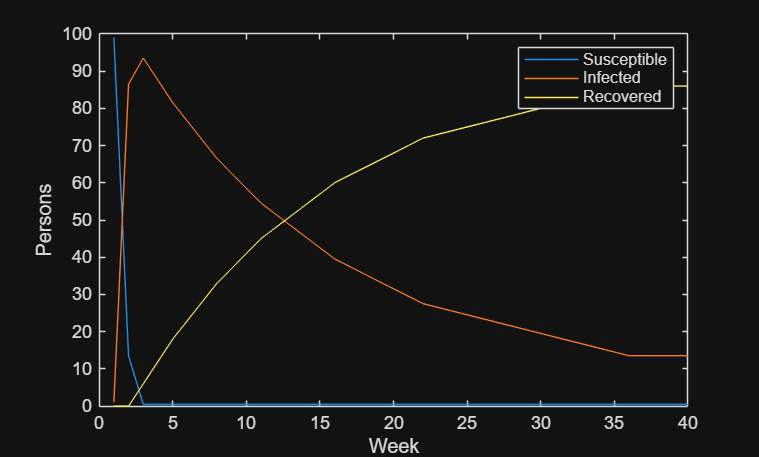

mi = 0.9600

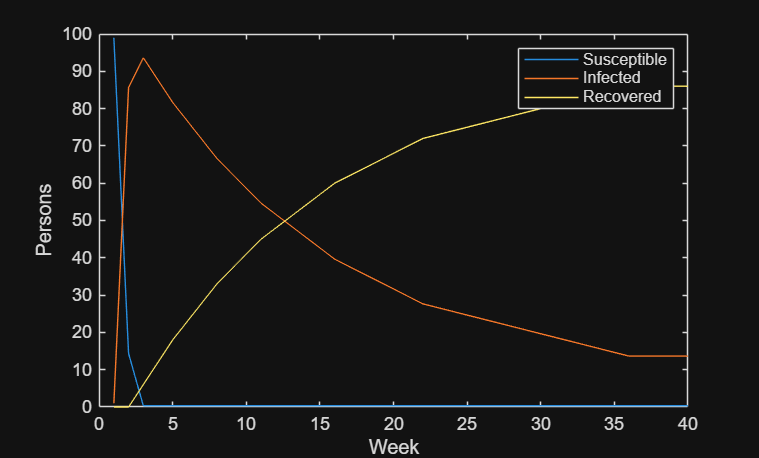

mi = 0.9500

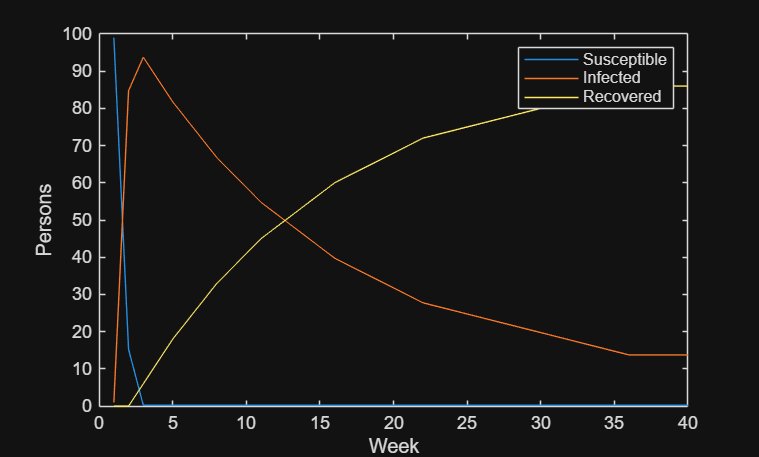

mi = 0.9400

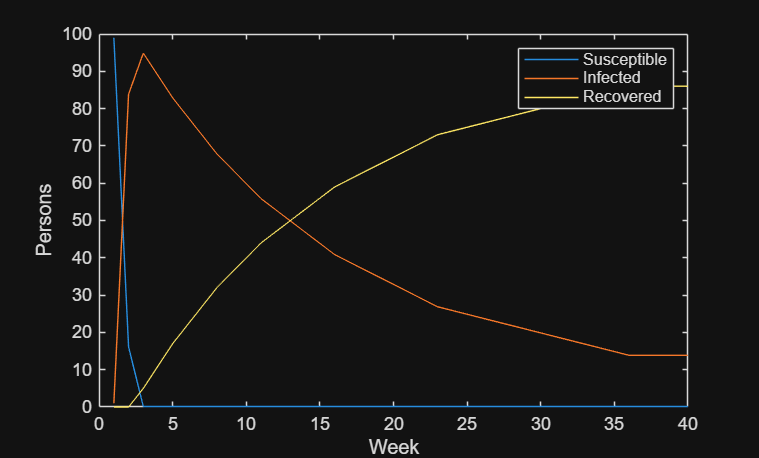

mi = 0.9300

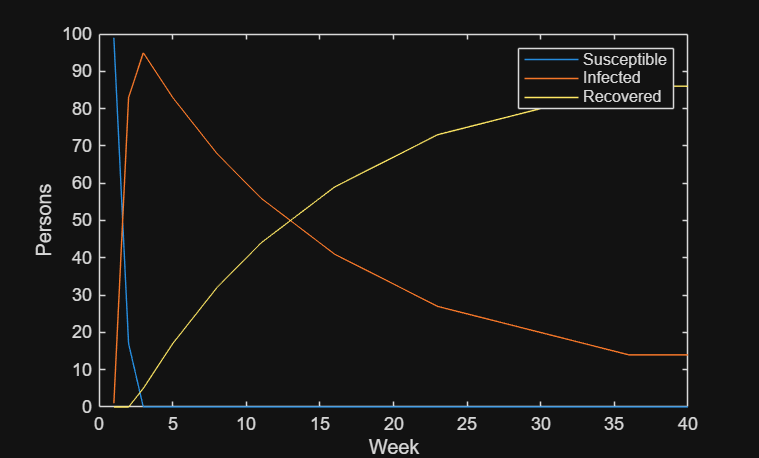

mi = 0.9200

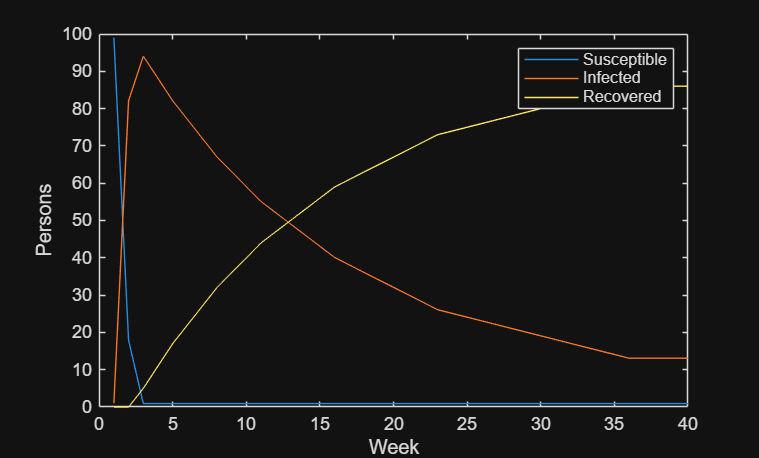

mi = 0.9100

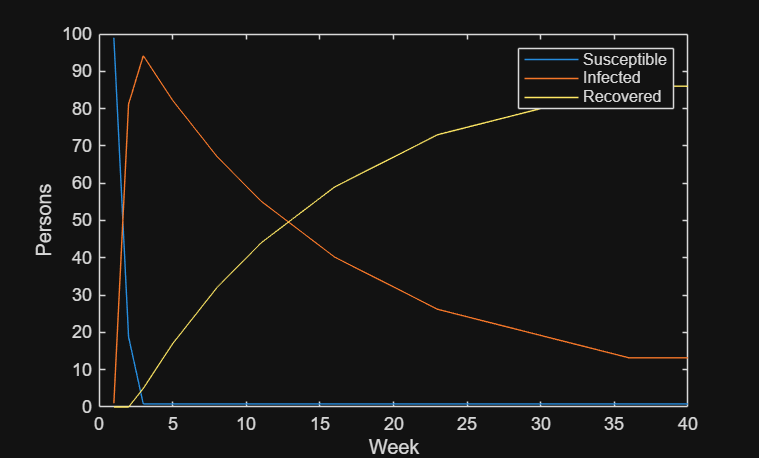

mi = 0.9000

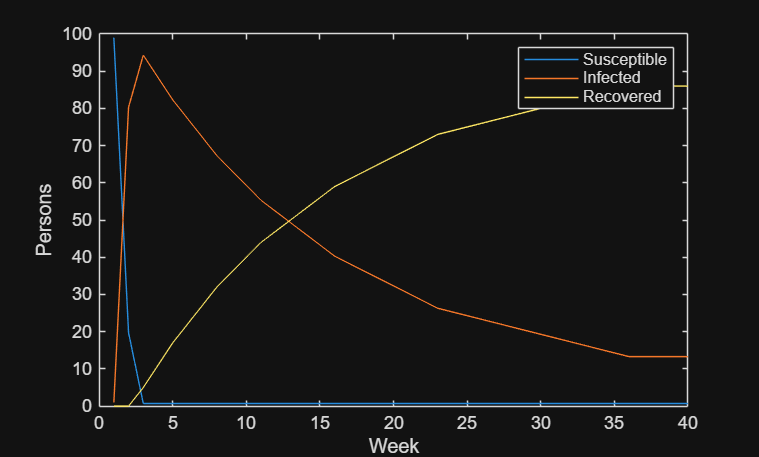

mi = 0.8900

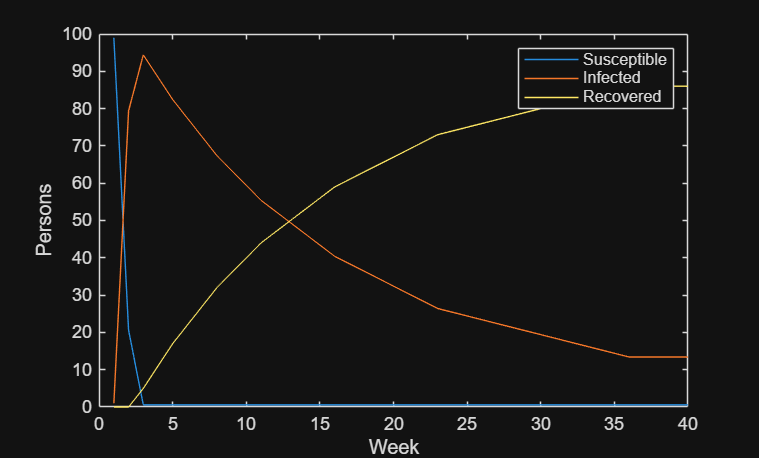

mi = 0.8800

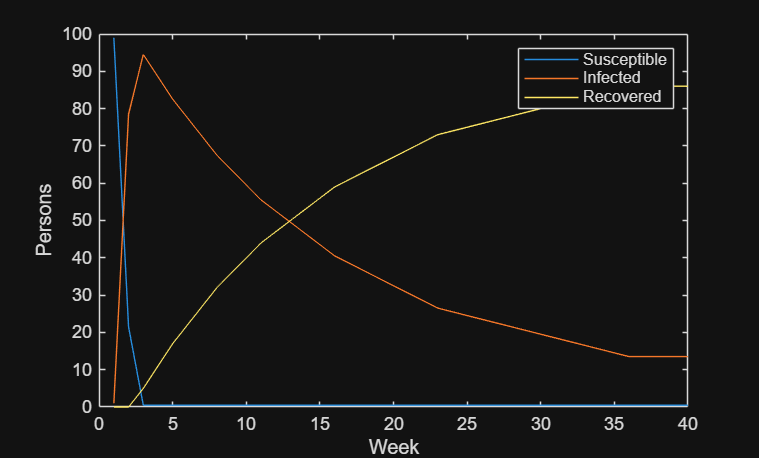

mi = 0.8700

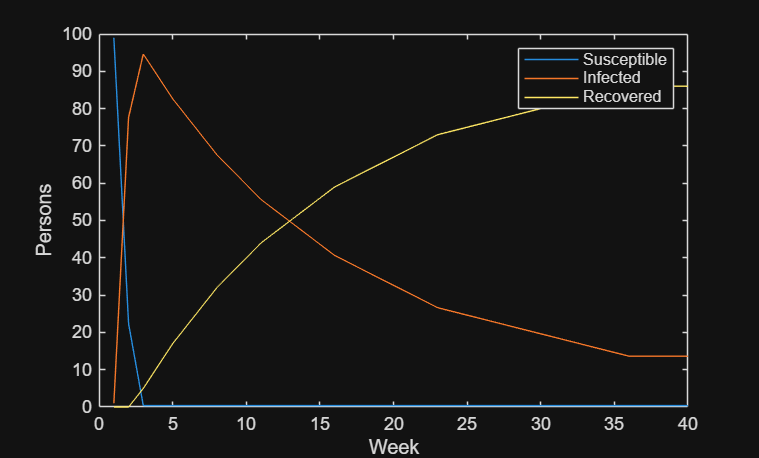

mi = 0.8600

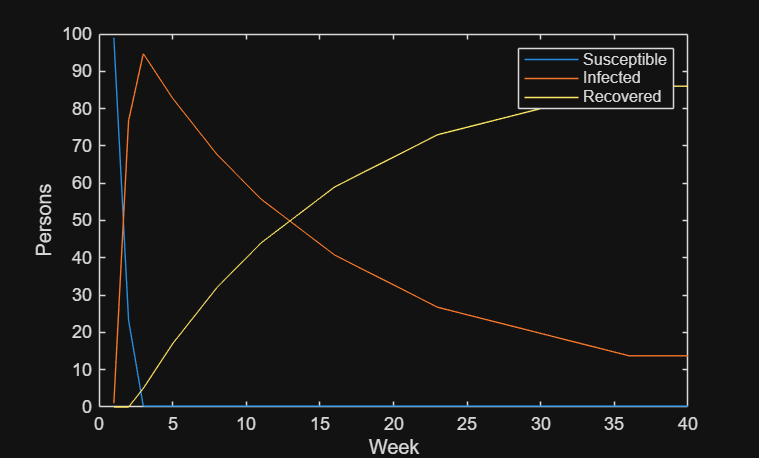

mi = 0.8500

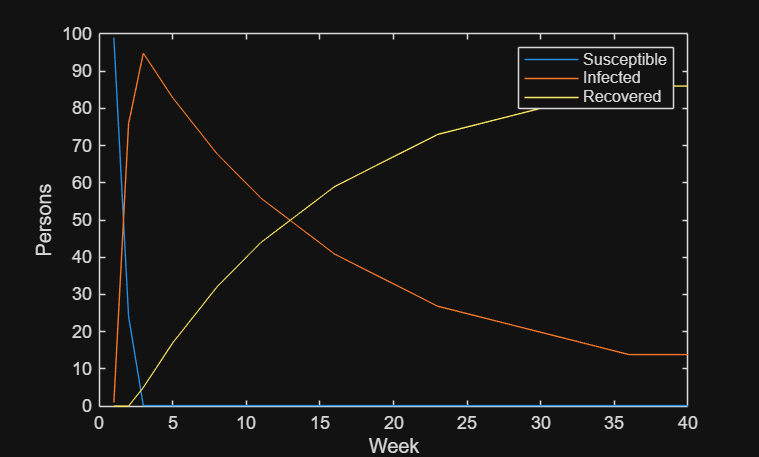

mi = 0.8400

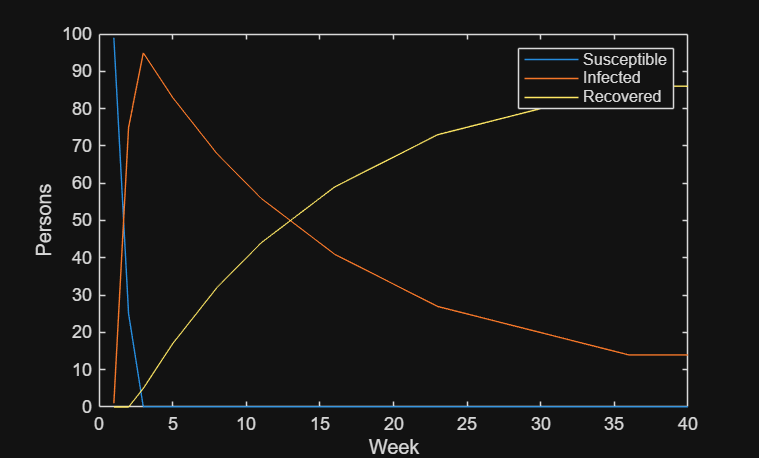

mi = 0.8300

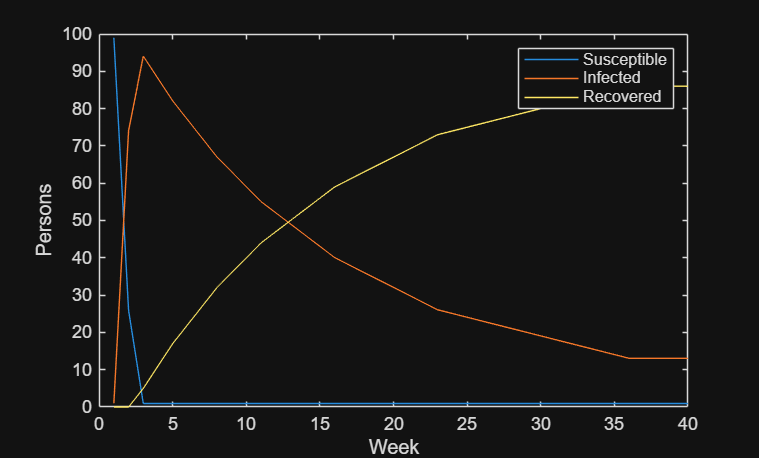

mi = 0.8200

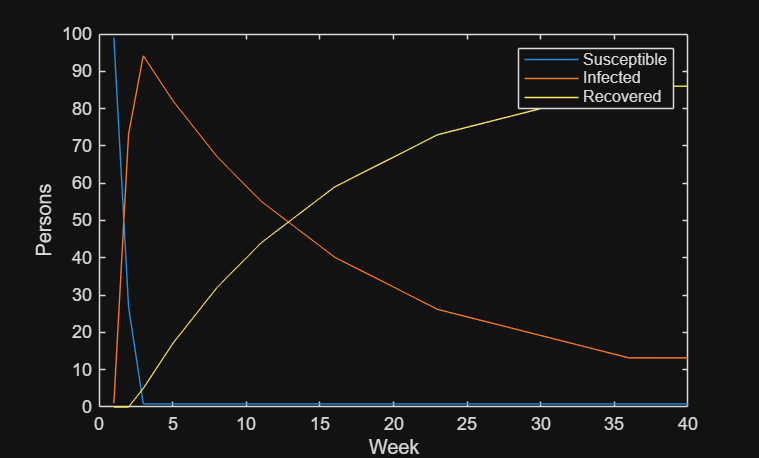

mi = 0.8100

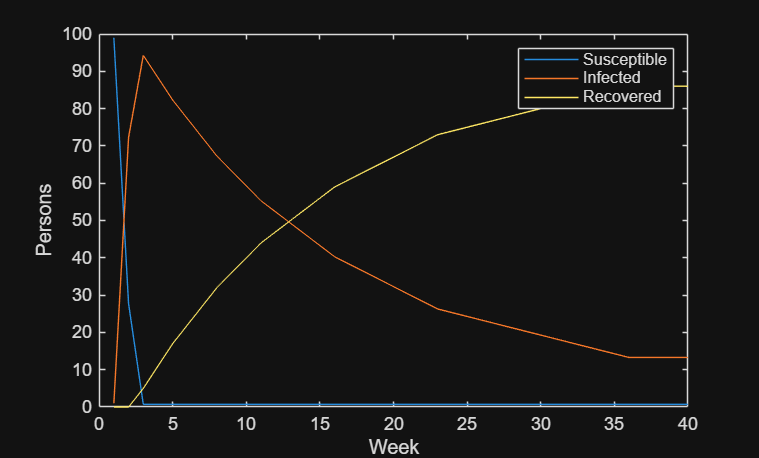

mi = 0.8000

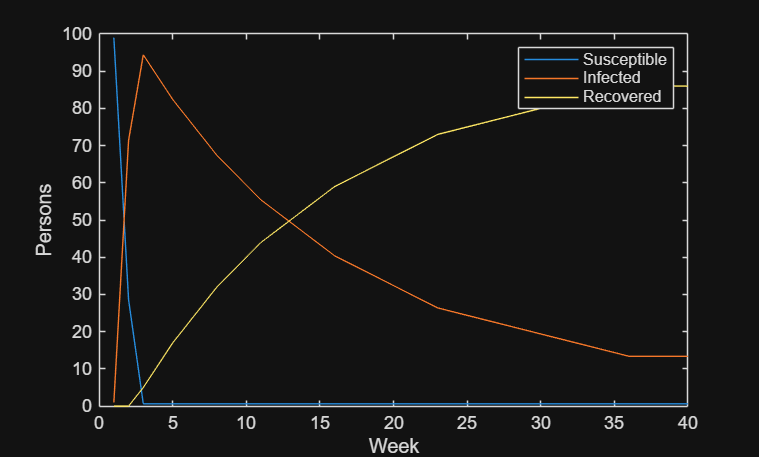

mi = 0.7900

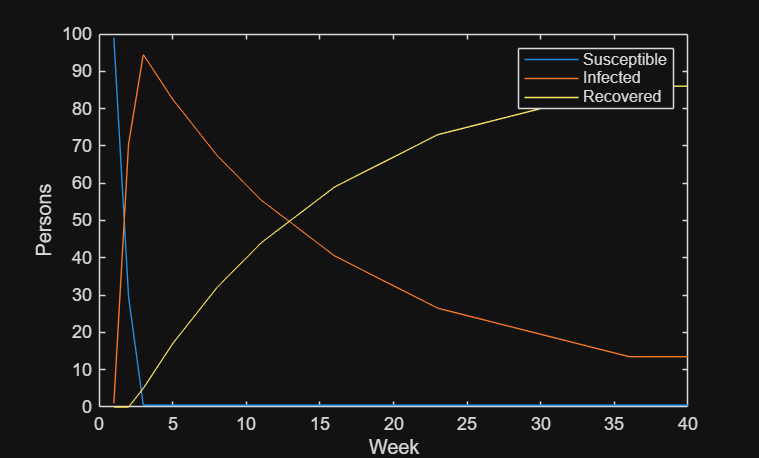

mi = 0.7800

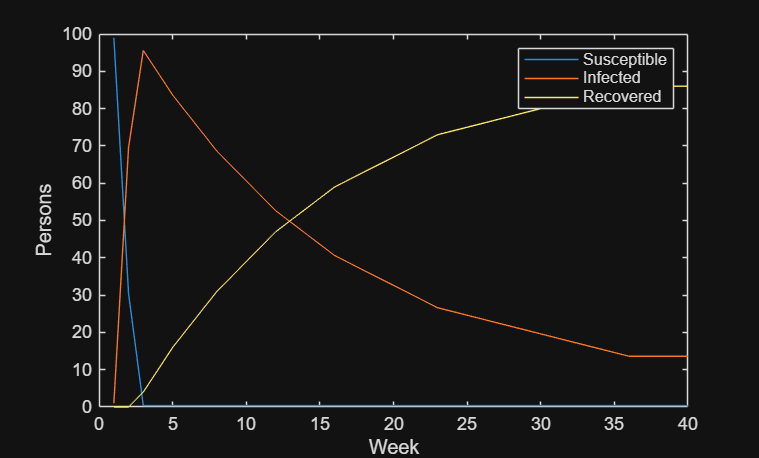

mi = 0.7700

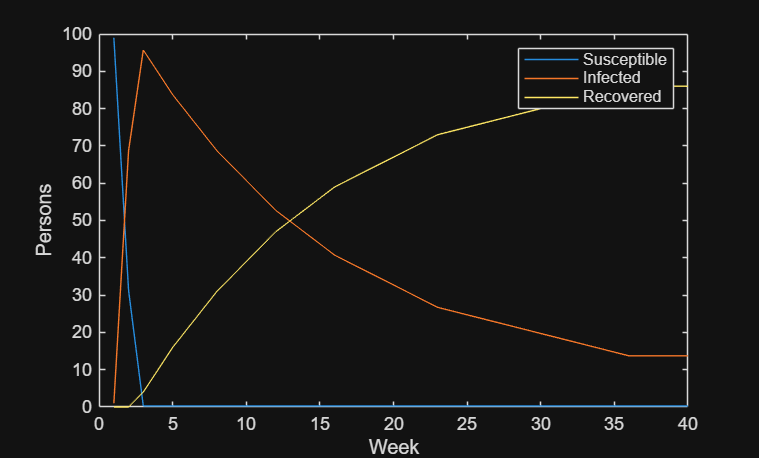

mi = 0.7600

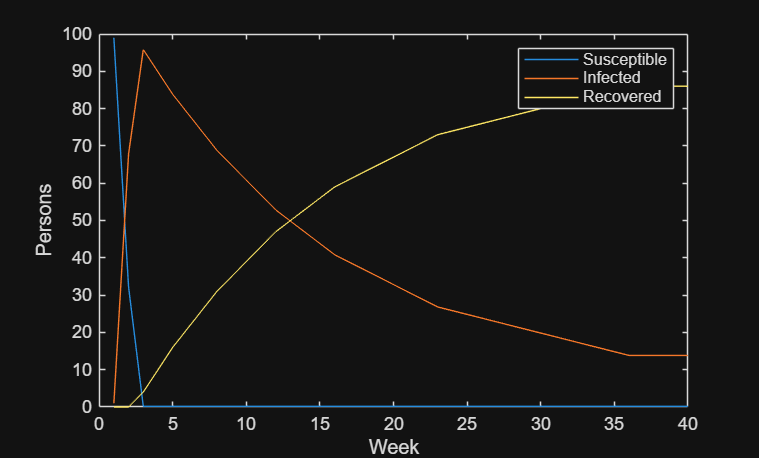

mi = 0.7500

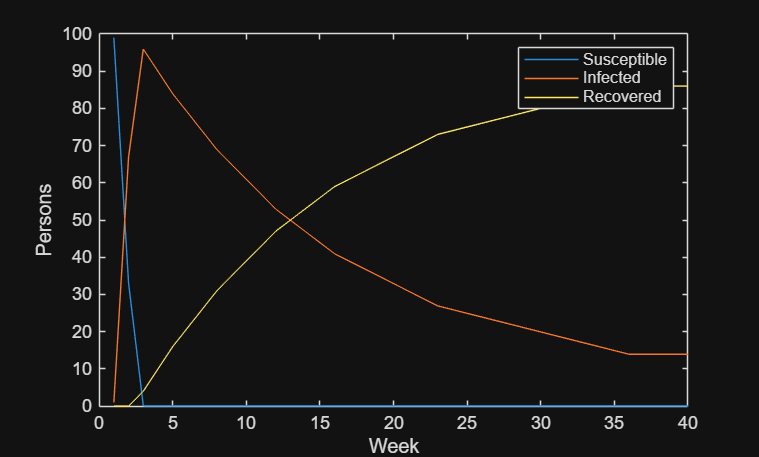

mi = 0.7400

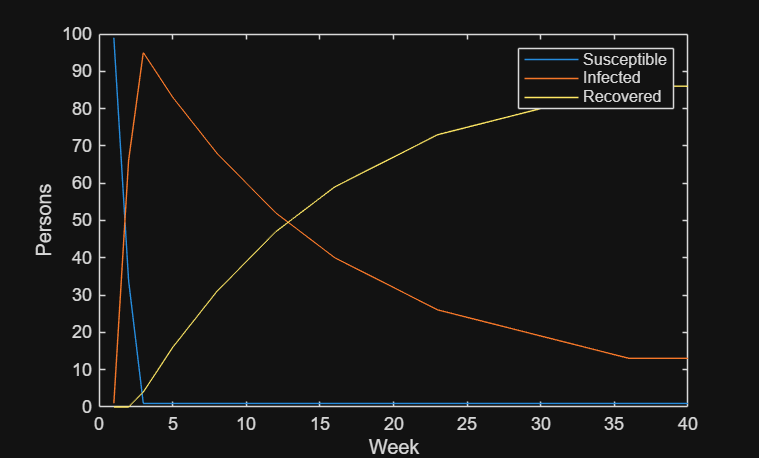

mi = 0.7300

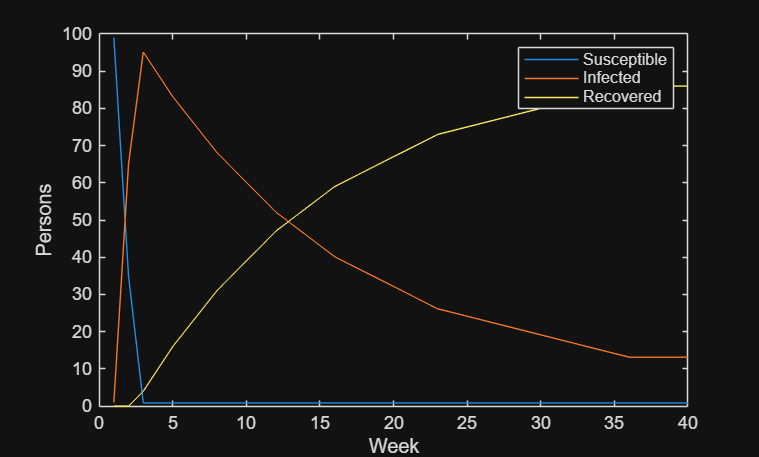

mi = 0.7200

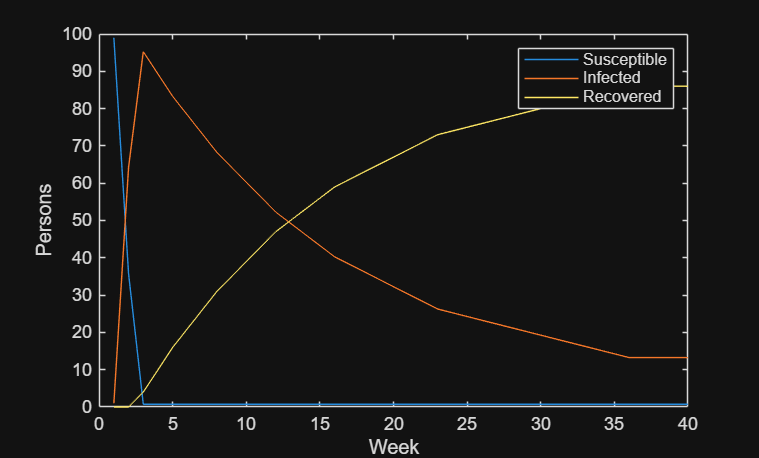

mi = 0.7100

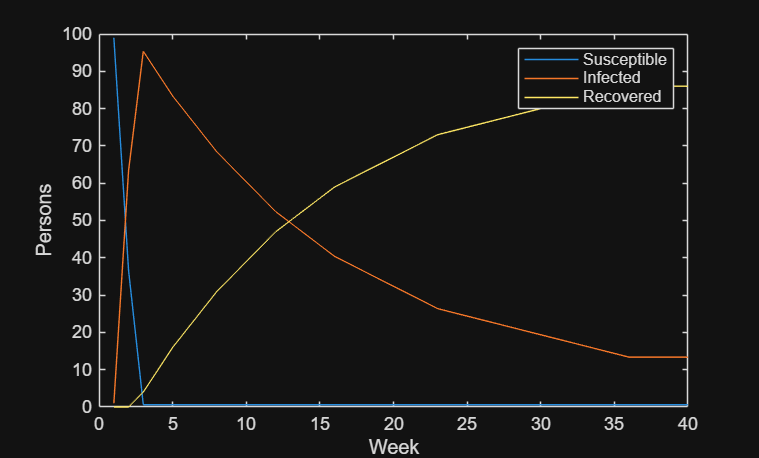

mi = 0.7000

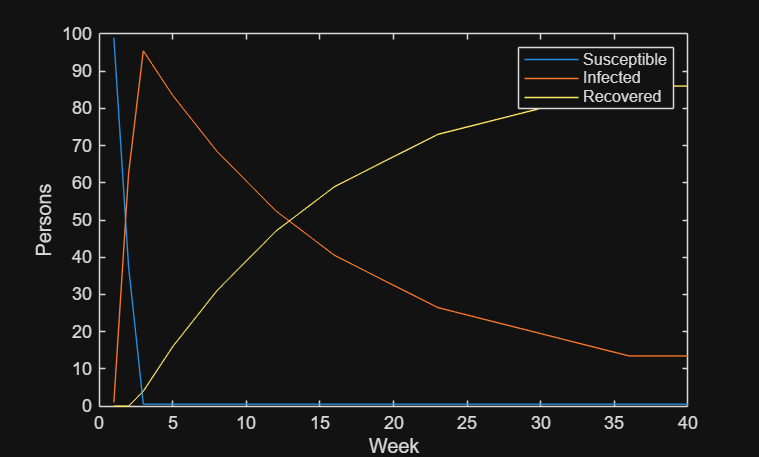

mi = 0.6900

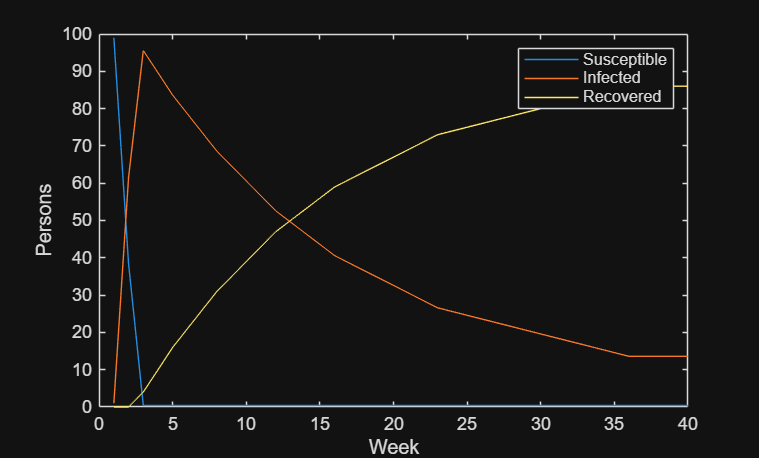

mi = 0.6800

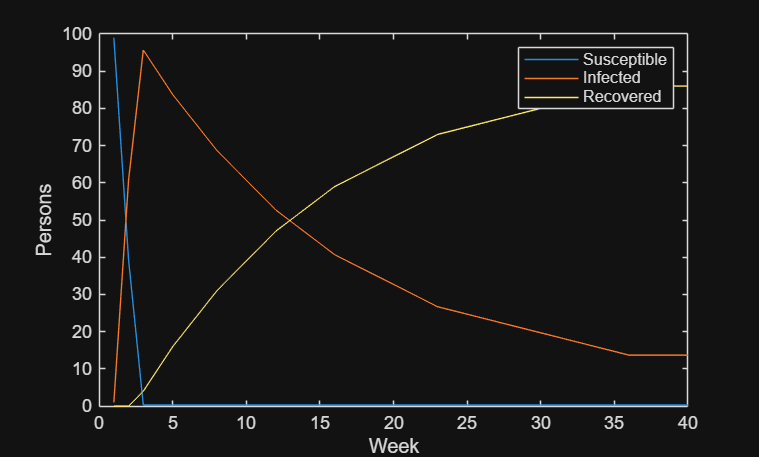

mi = 0.6700

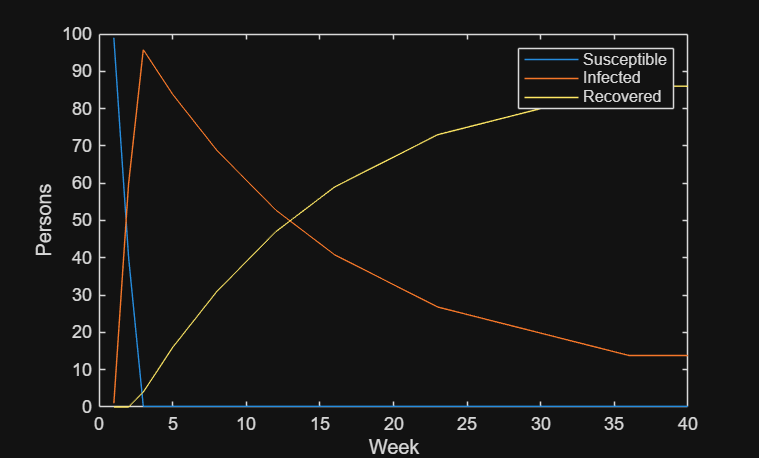

mi = 0.6600

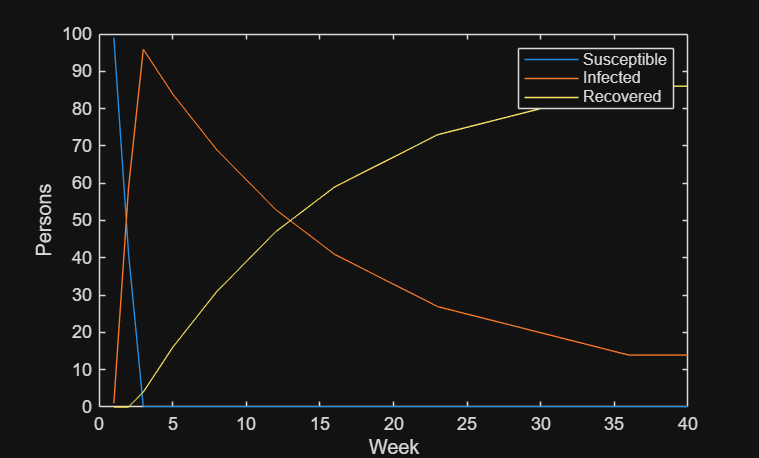

mi = 0.6500

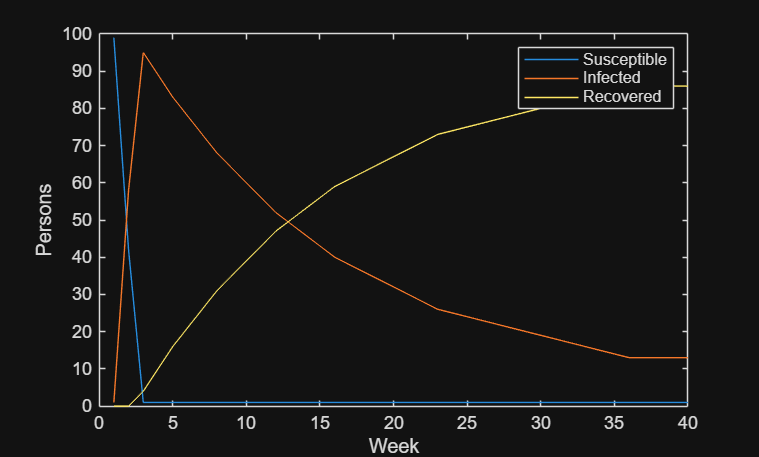

mi = 0.6400

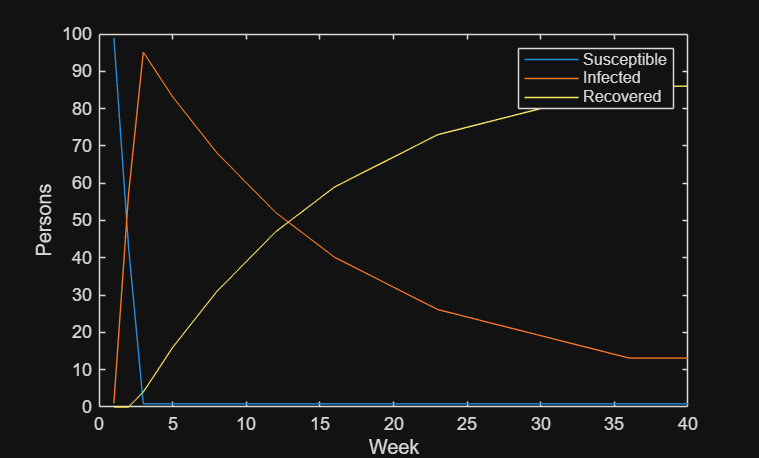

mi = 0.6300

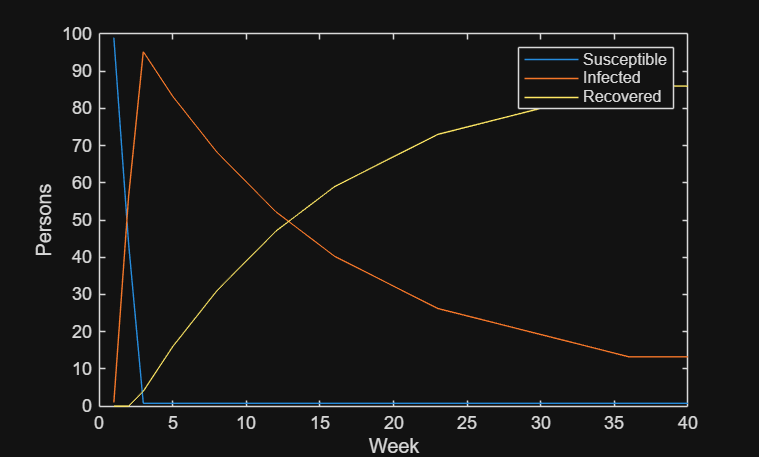

mi = 0.6200

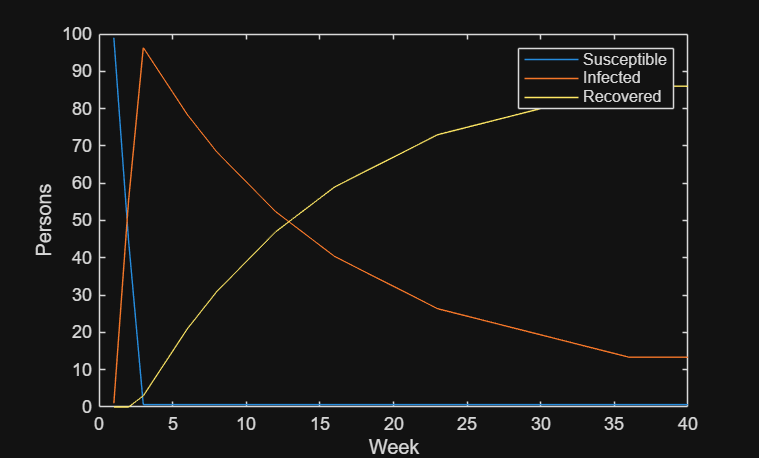

mi = 0.6100

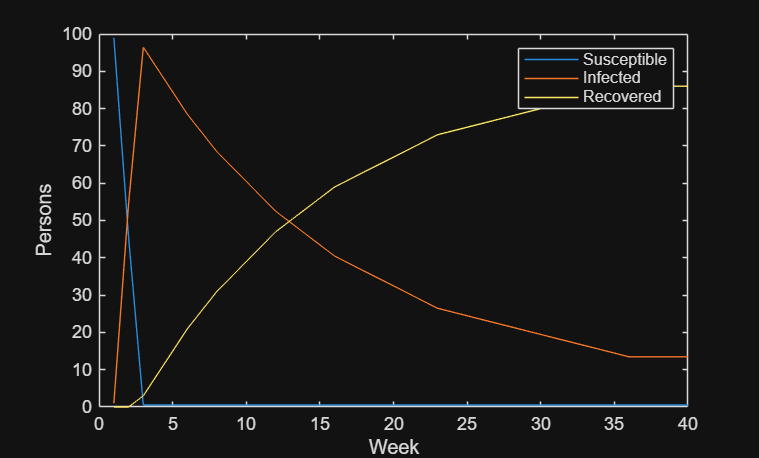

mi = 0.6000

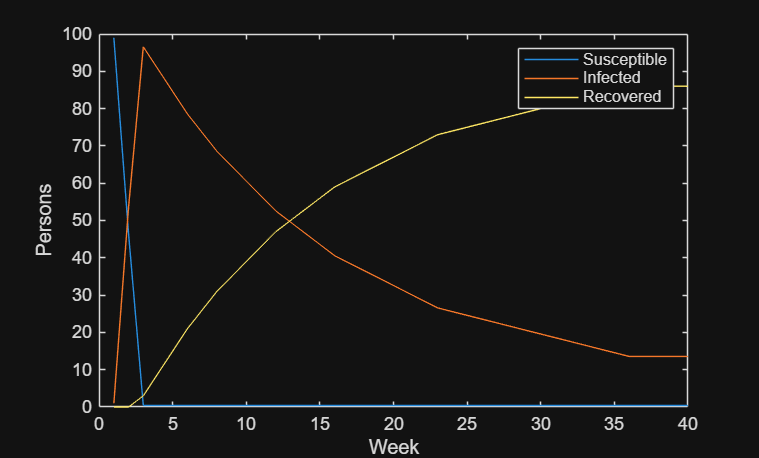

mi = 0.5900

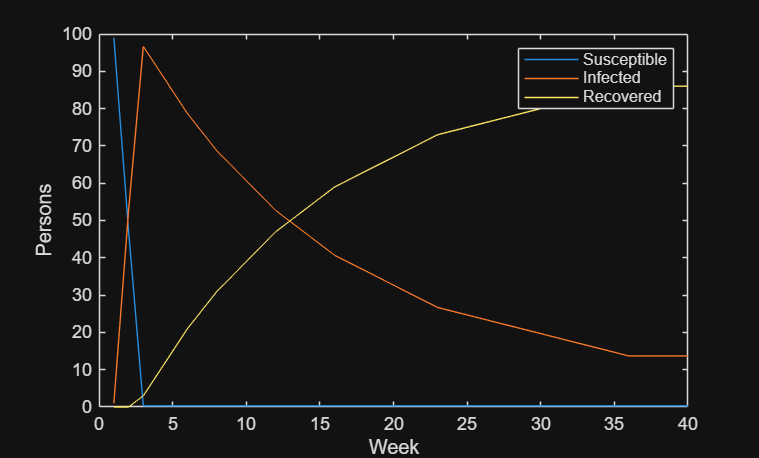

mi = 0.5800

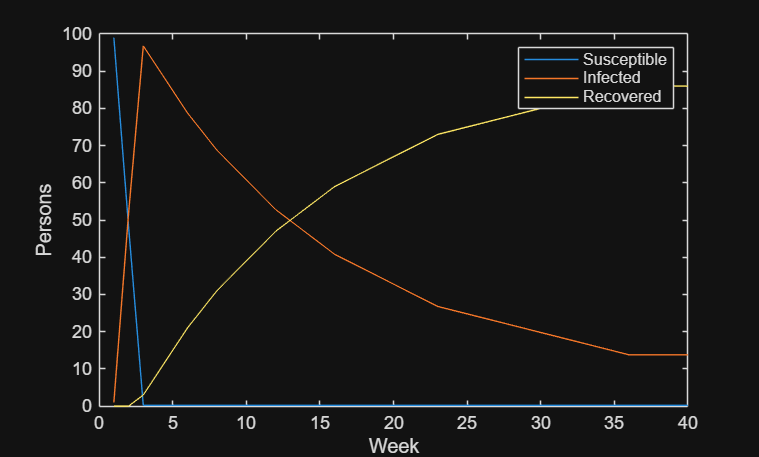

mi = 0.5700

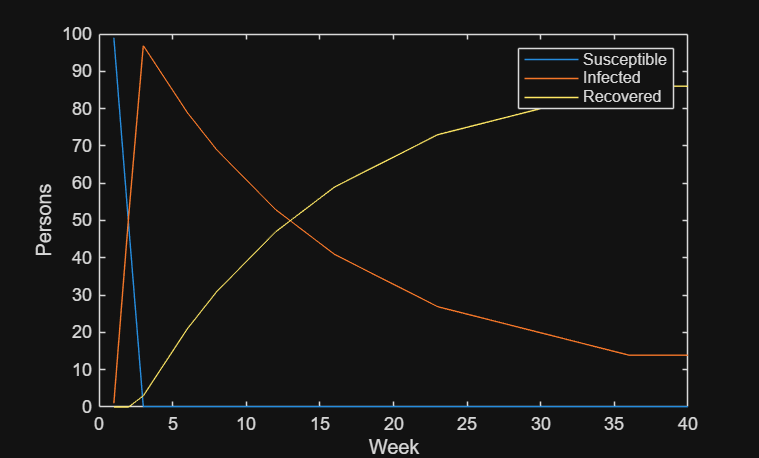

mi = 0.5600

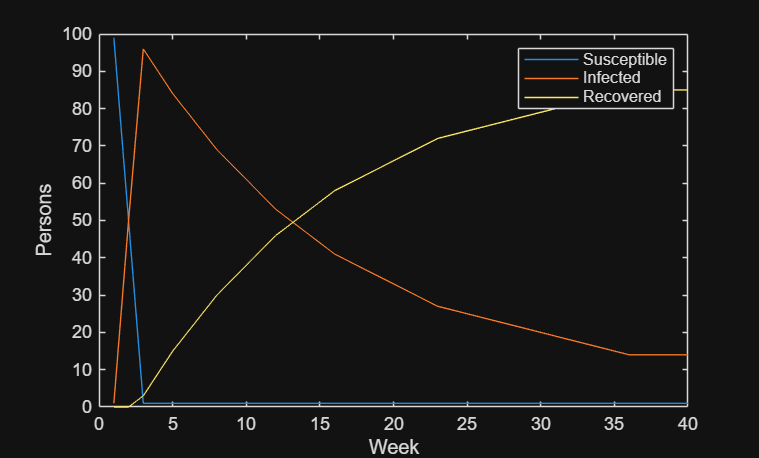

mi = 0.5500

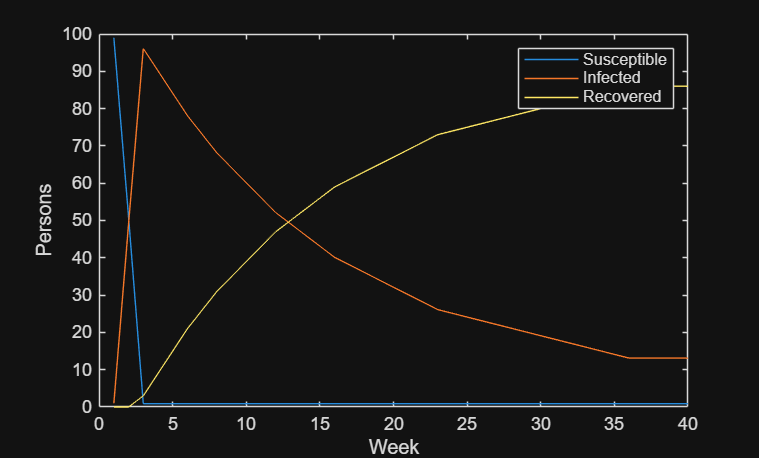

mi = 0.5400

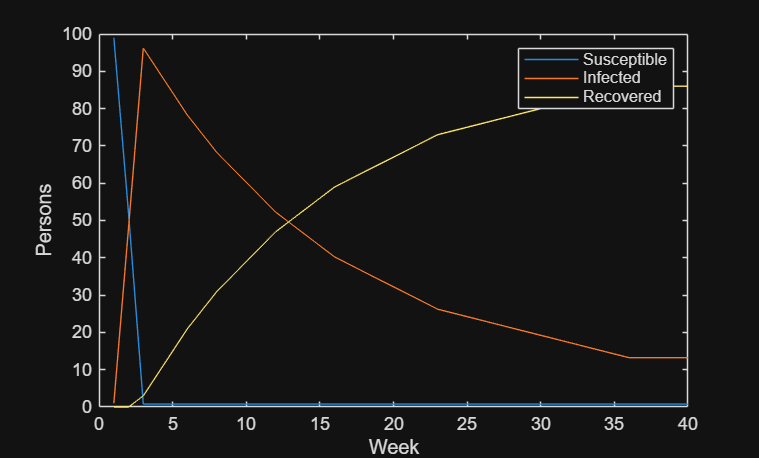

mi = 0.5300

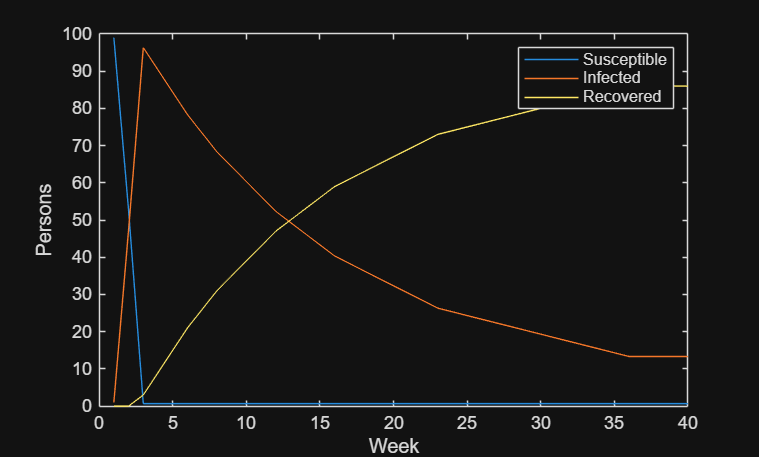

mi = 0.5200

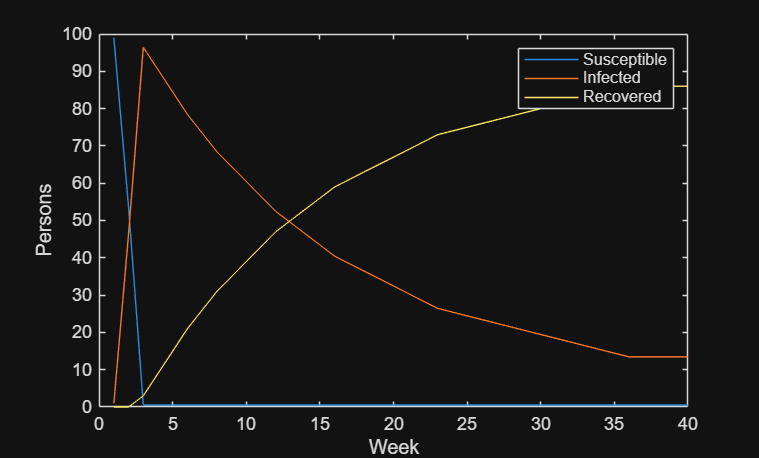

mi = 0.5100

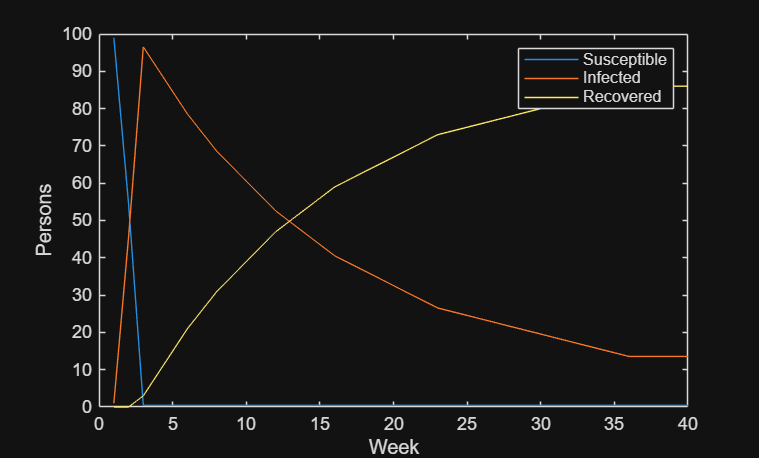

mi = 0.5000

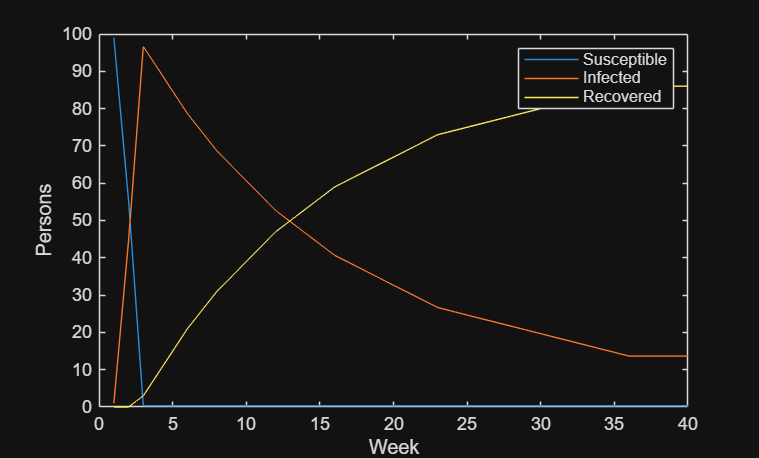

mi = 0.4900

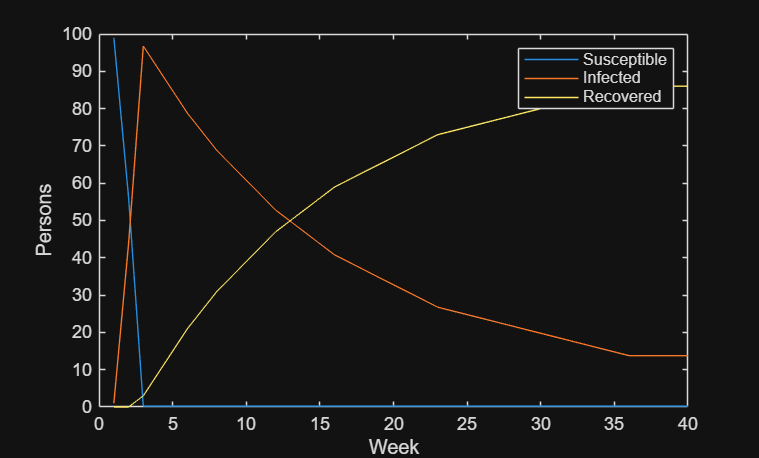

mi = 0.4800

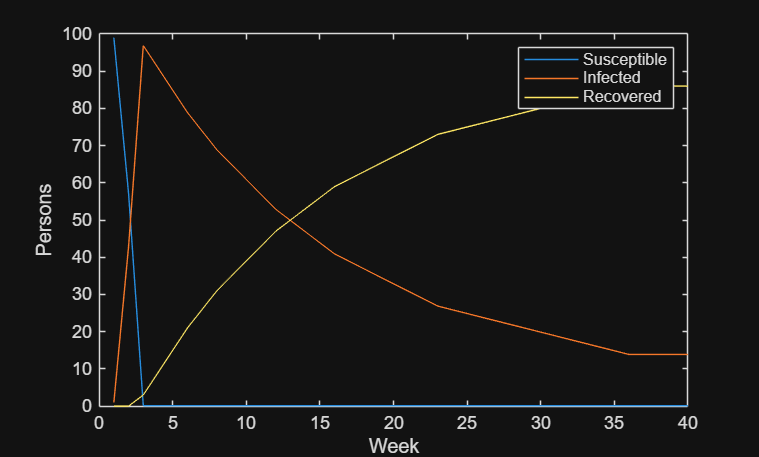

mi = 0.4700

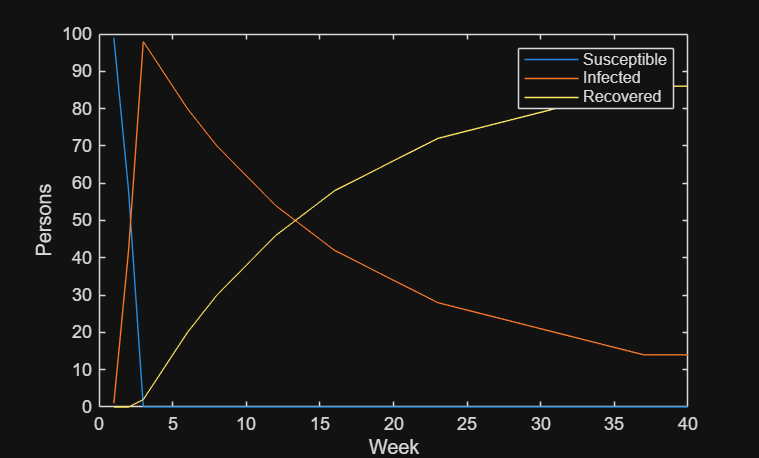

mi = 0.4600

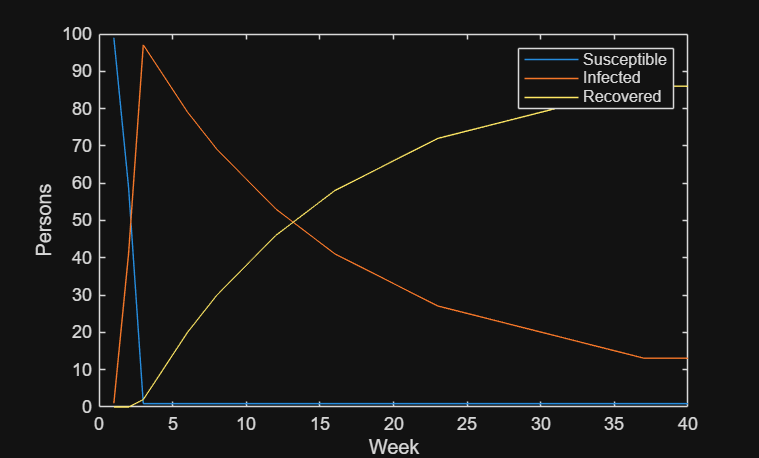

mi = 0.4500

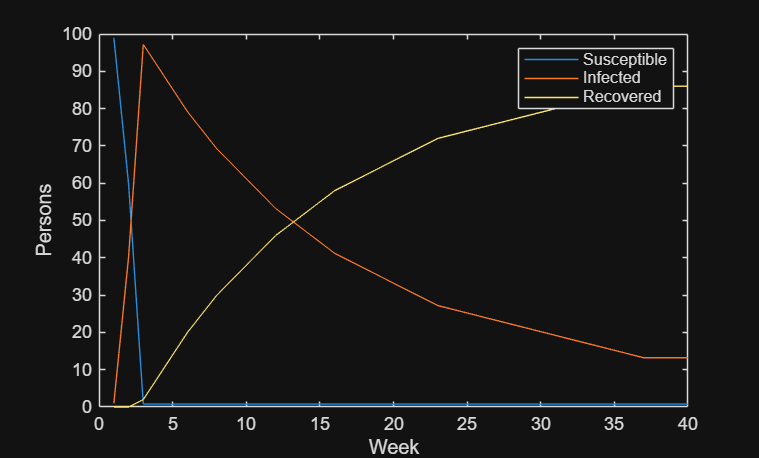

mi = 0.4400

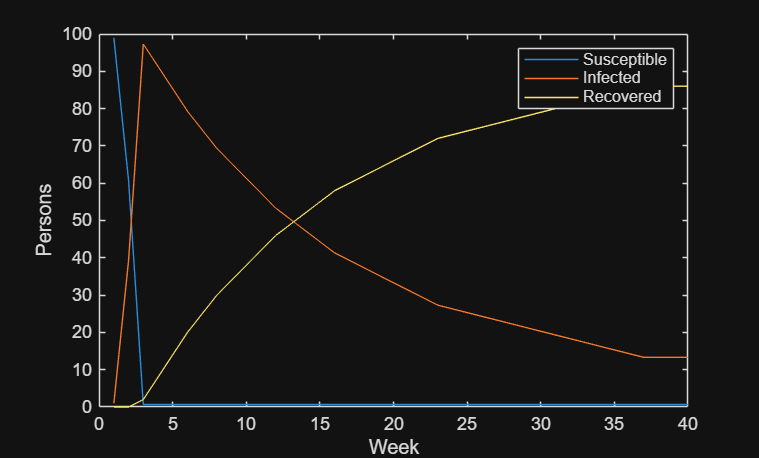

mi = 0.4300

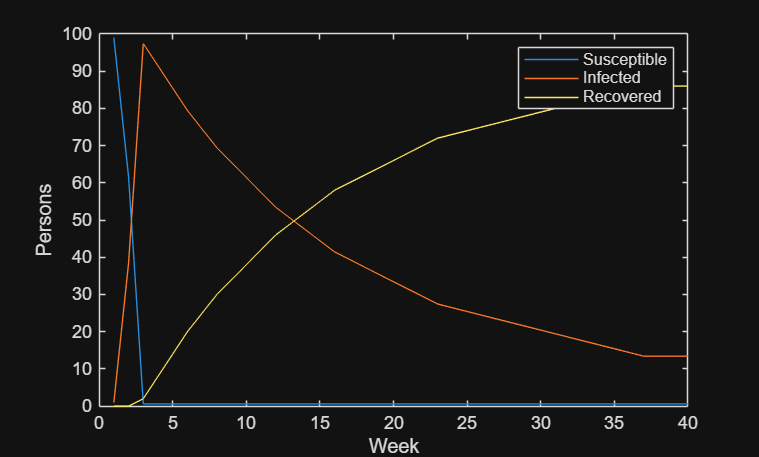

mi = 0.4200

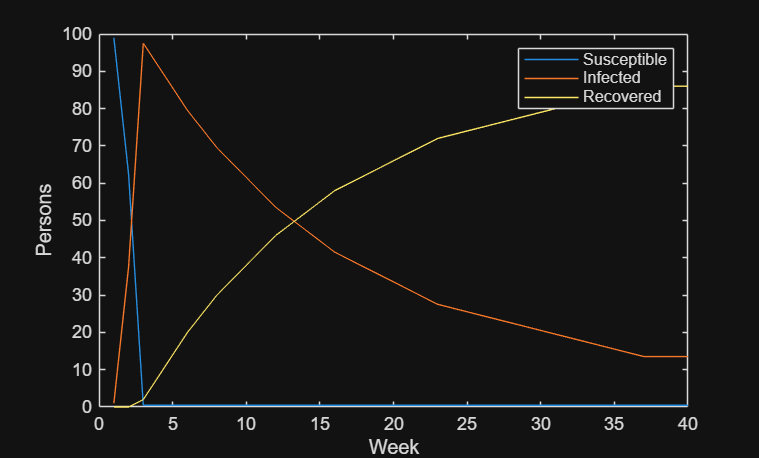

mi = 0.4100

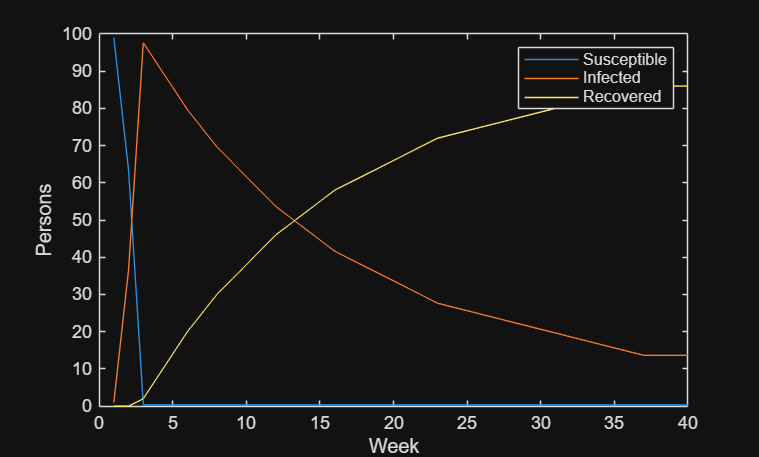

mi = 0.4000

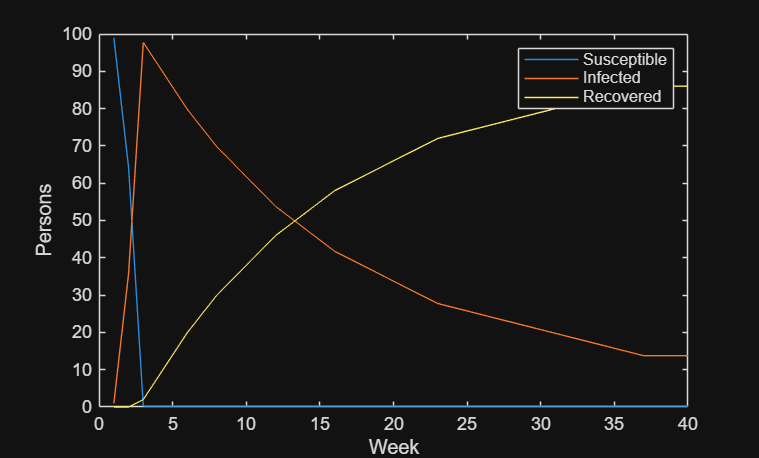

mi = 0.3900

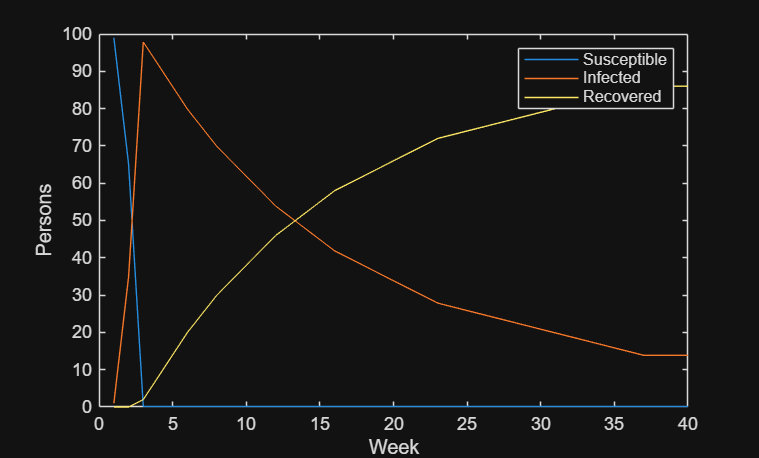

mi = 0.3800

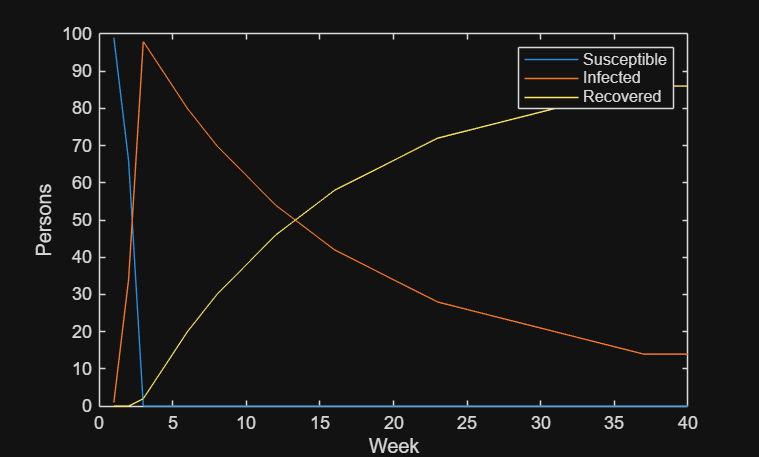

mi = 0.3700

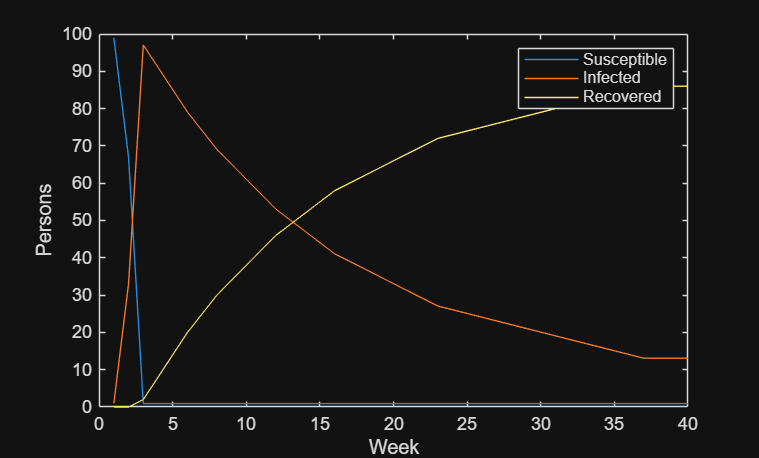

mi = 0.3600

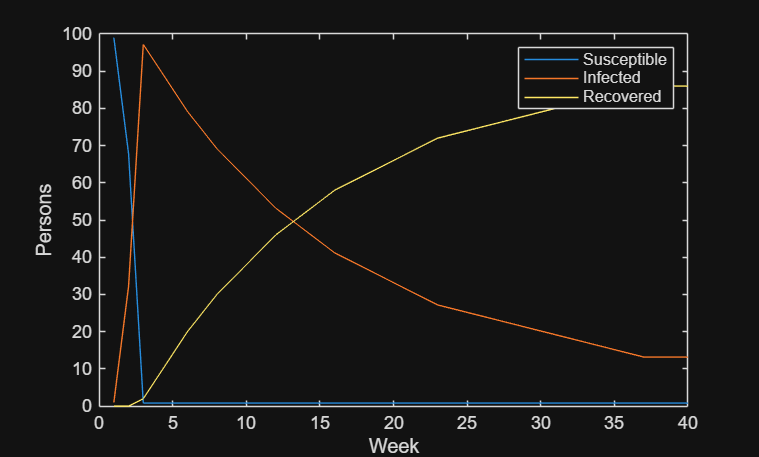

mi = 0.3500

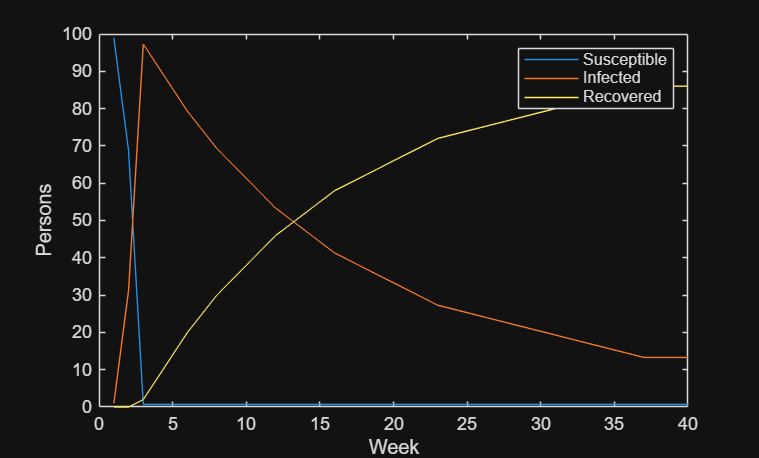

mi = 0.3400

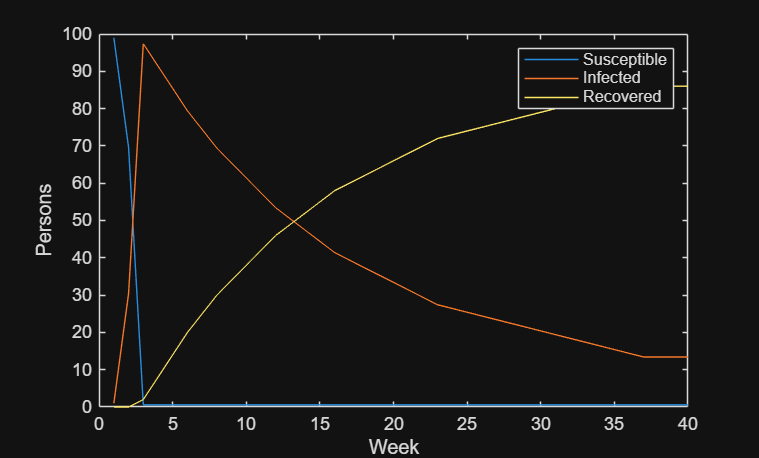

mi = 0.3300

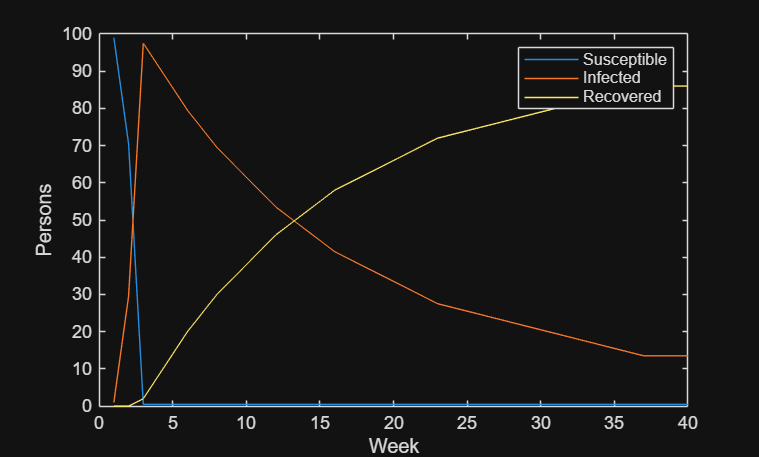

mi = 0.3200

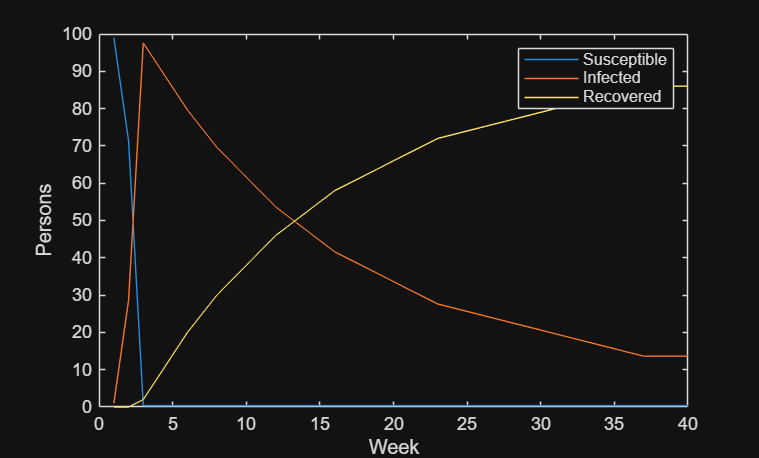

mi = 0.3100

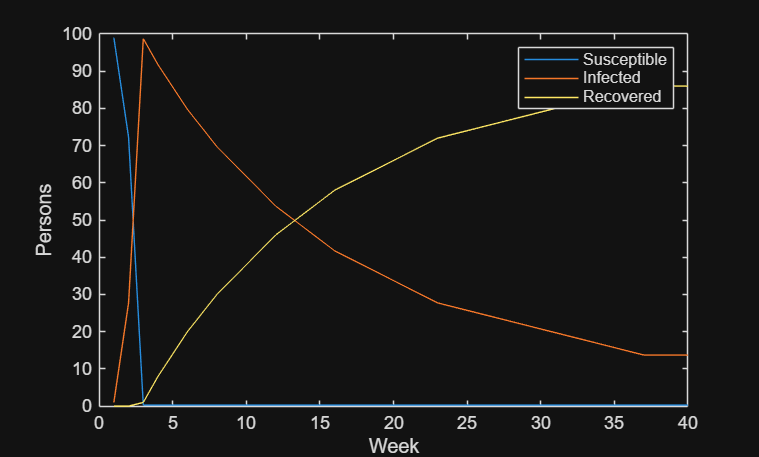

mi = 0.3000

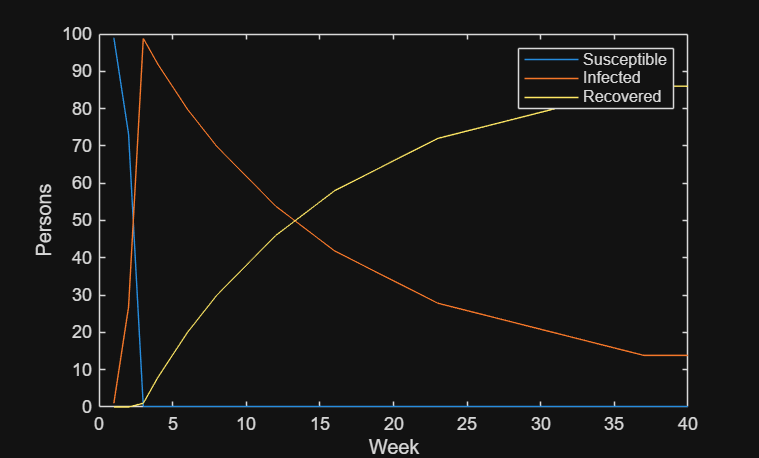

mi = 0.2900

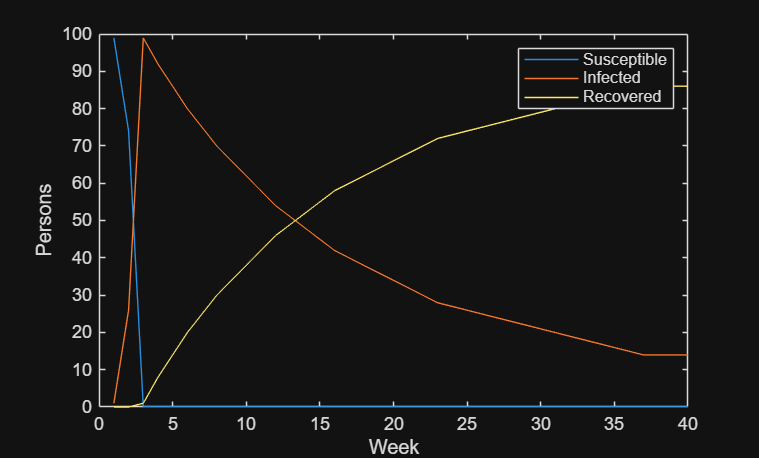

mi = 0.2800

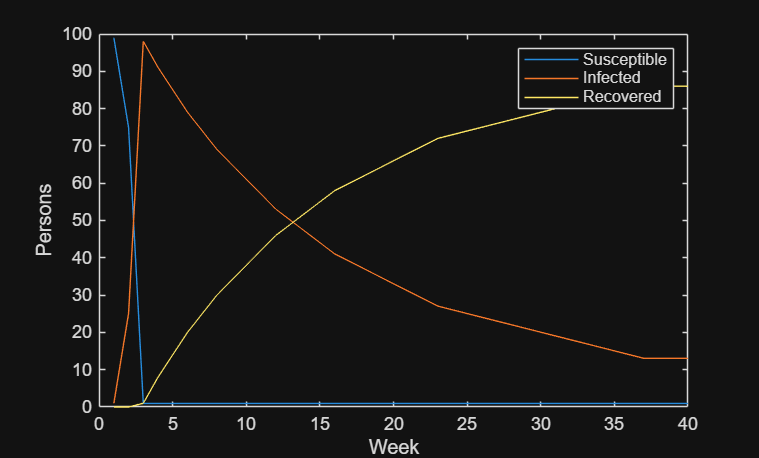

mi = 0.2700

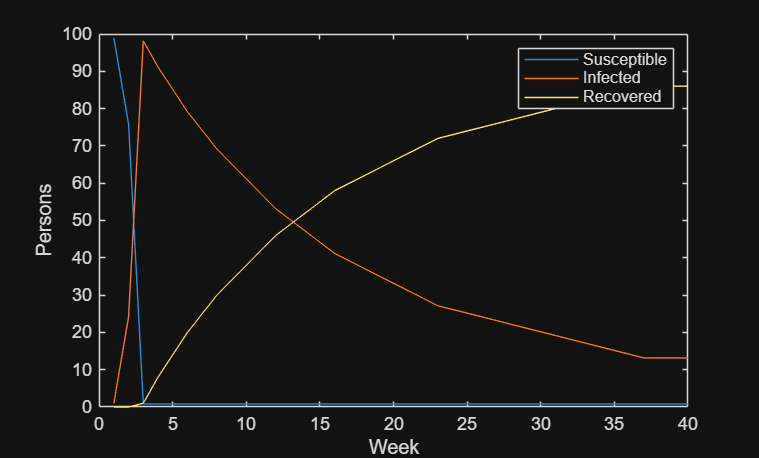

mi = 0.2600

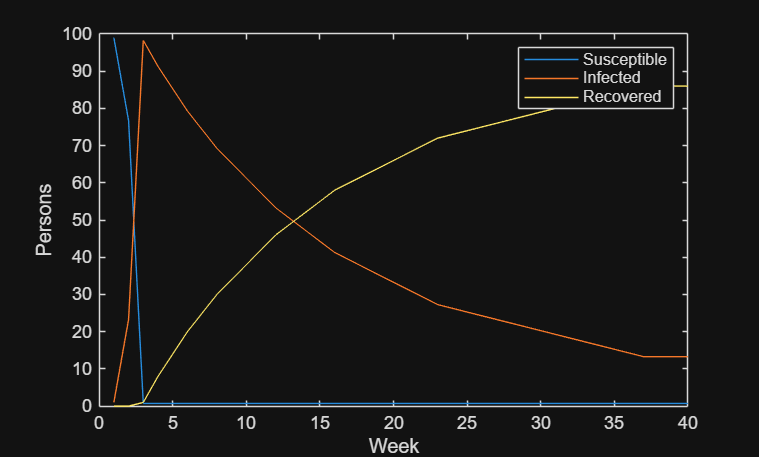

mi = 0.2500

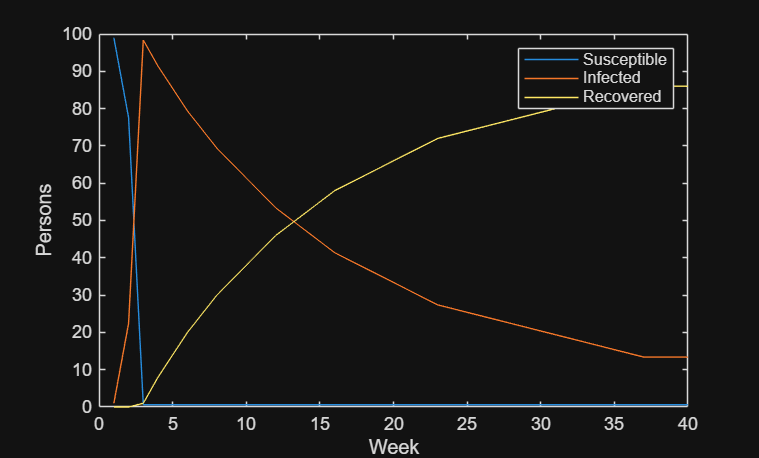

mi = 0.2400

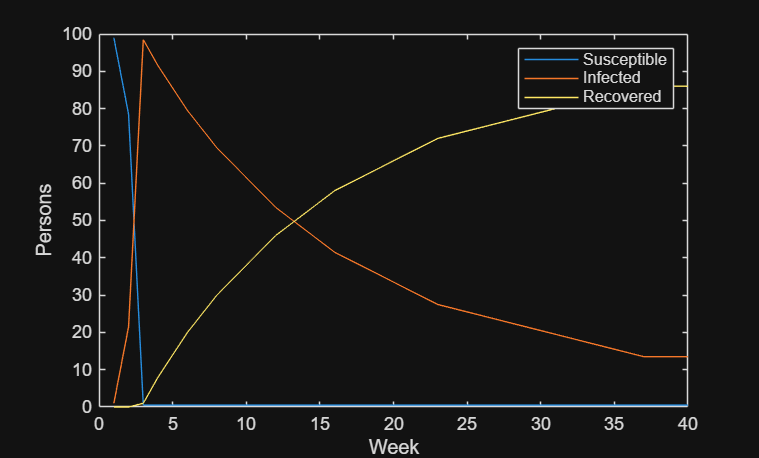

mi = 0.2300

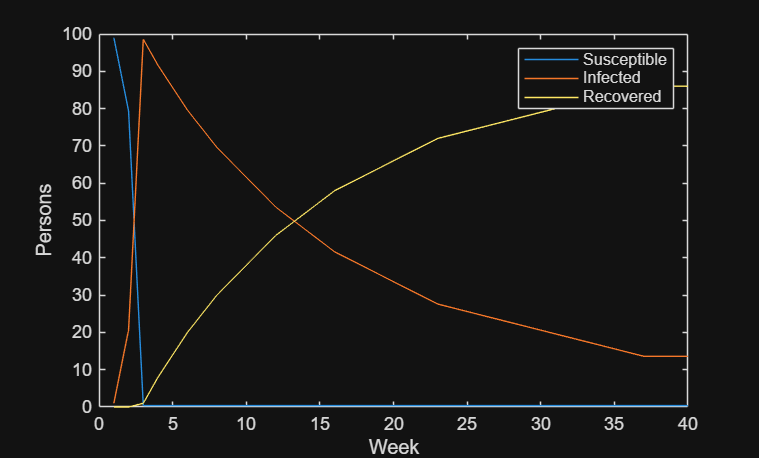

mi = 0.2200

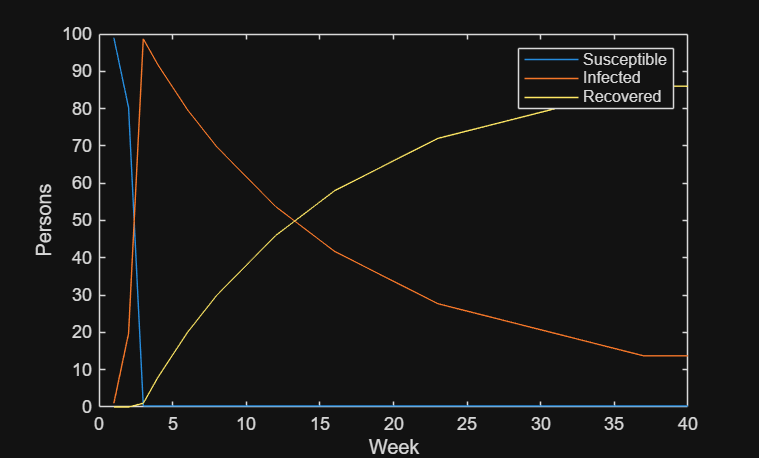

mi = 0.2100

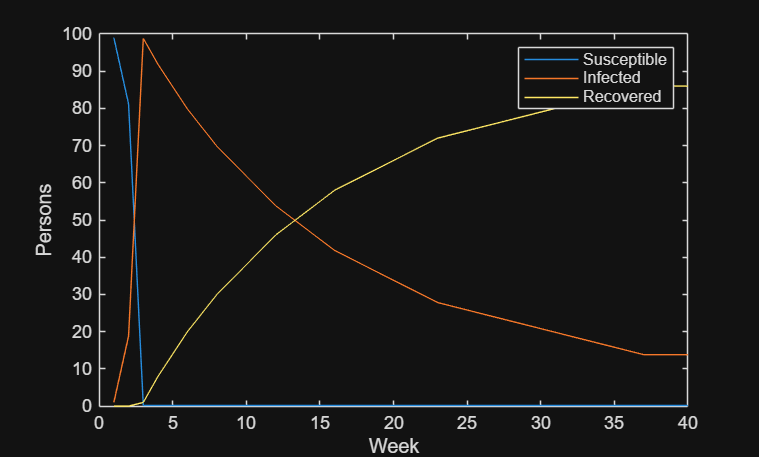

mi = 0.2000

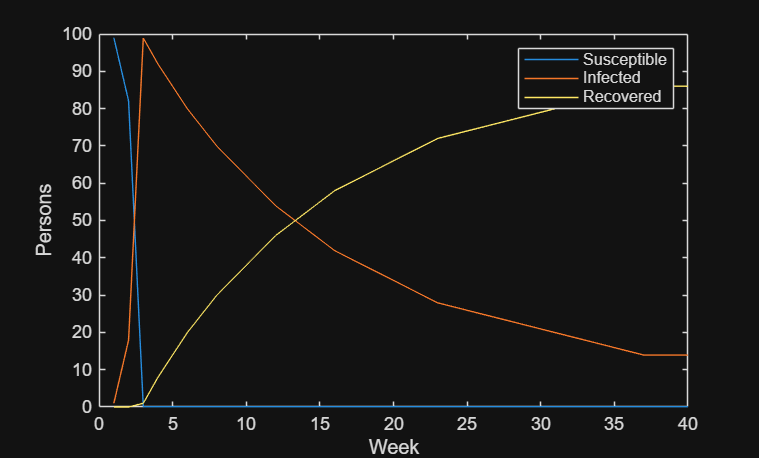

mi = 0.1900

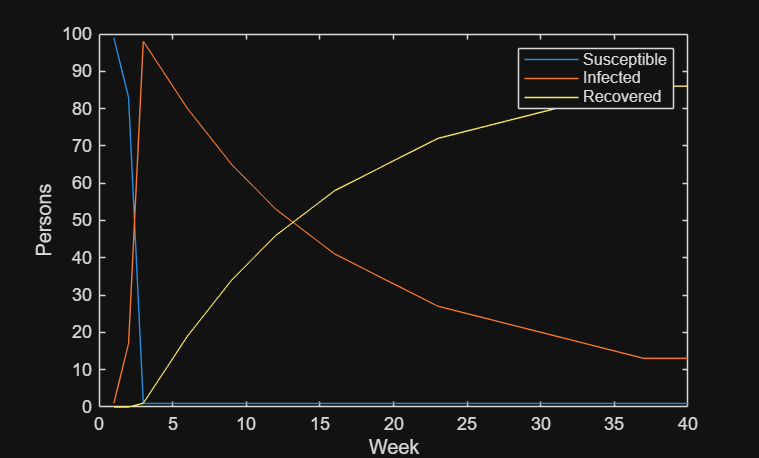

mi = 0.1800

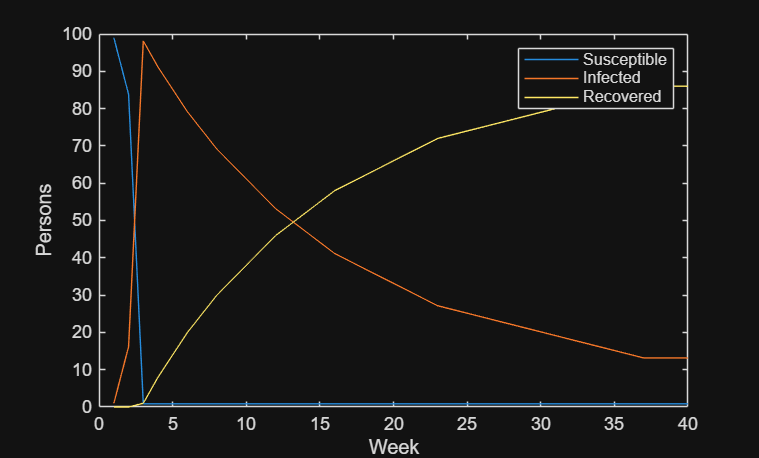

mi = 0.1700

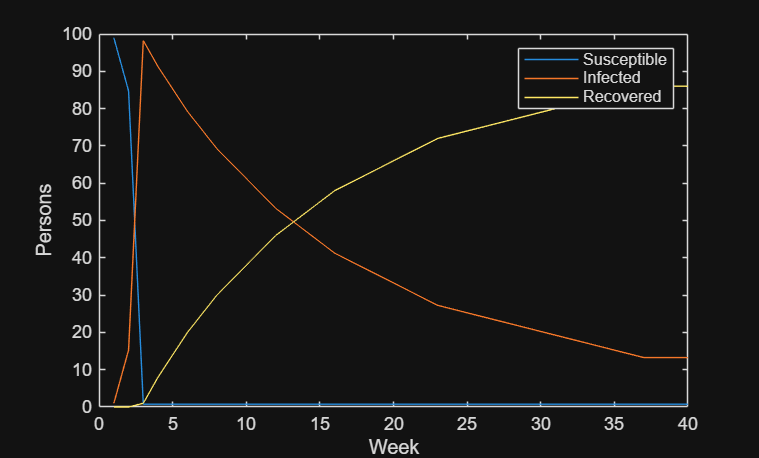

mi = 0.1600

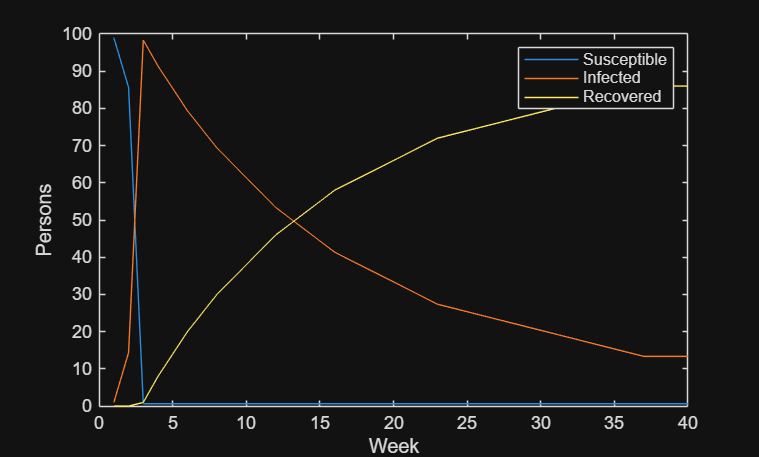

mi = 0.1500

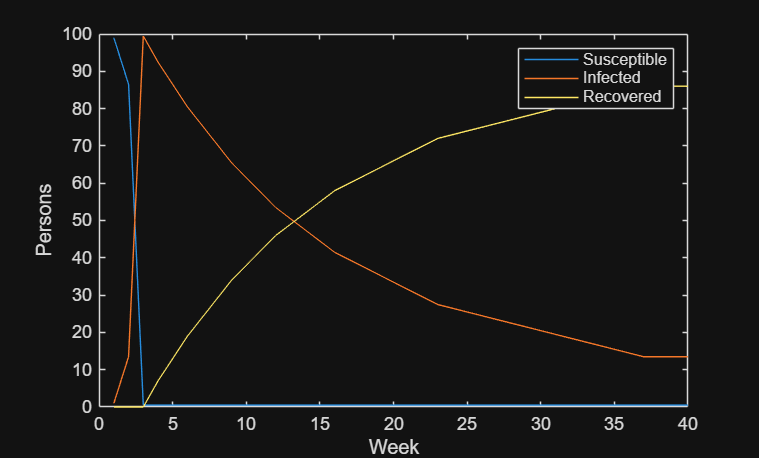

mi = 0.1400

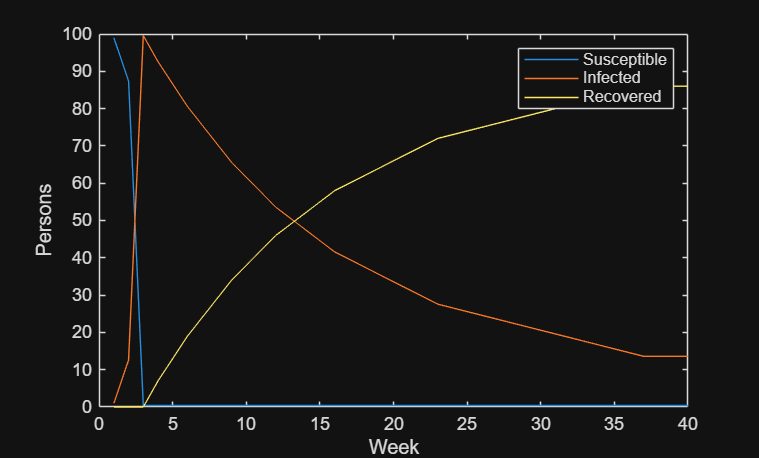

mi = 0.1300

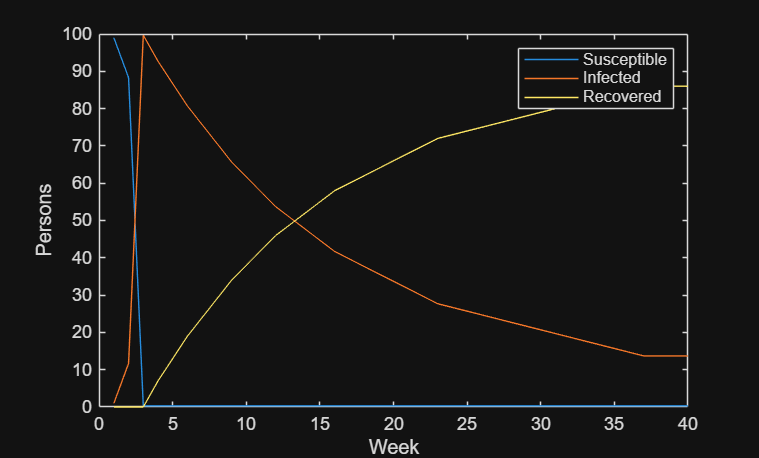

mi = 0.1200

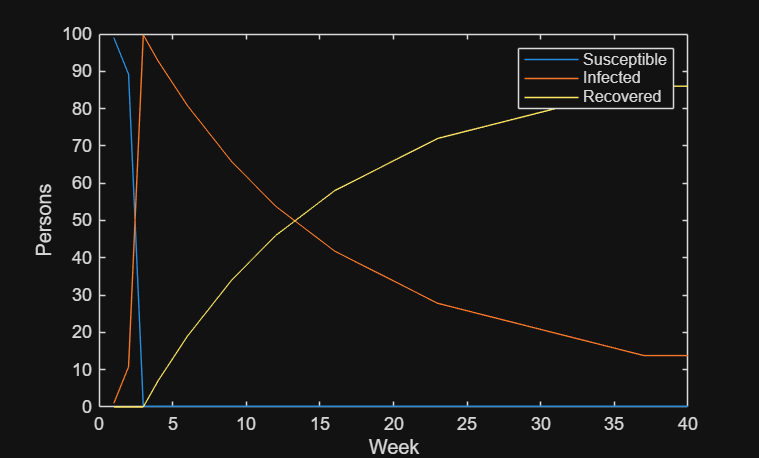

mi = 0.1100

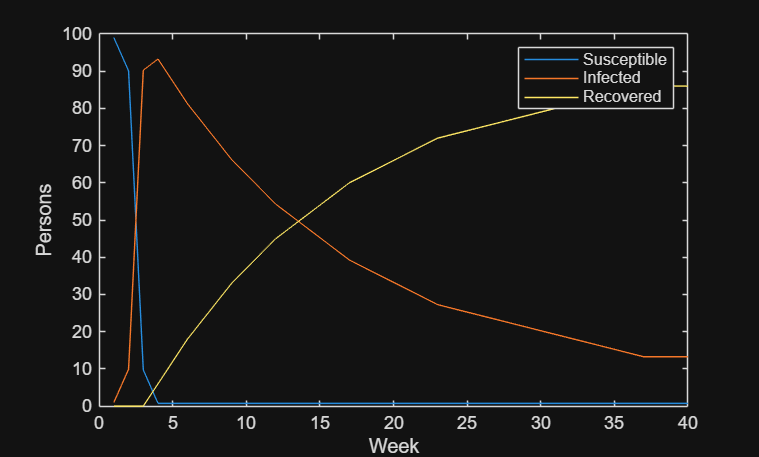

mi = 0.1000

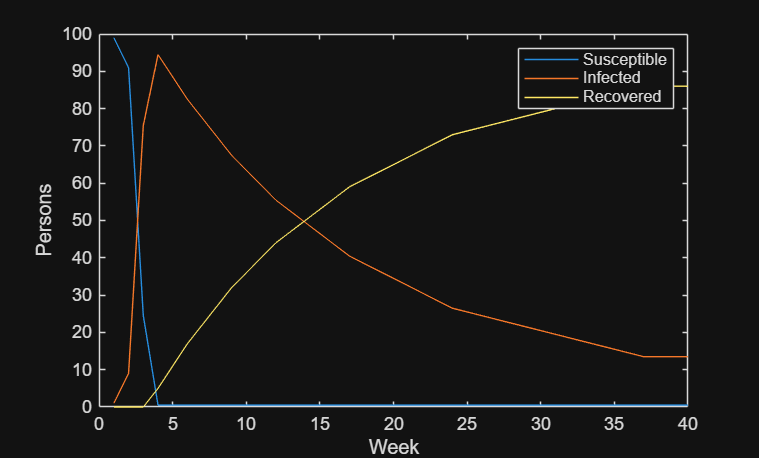

mi = 0.0900

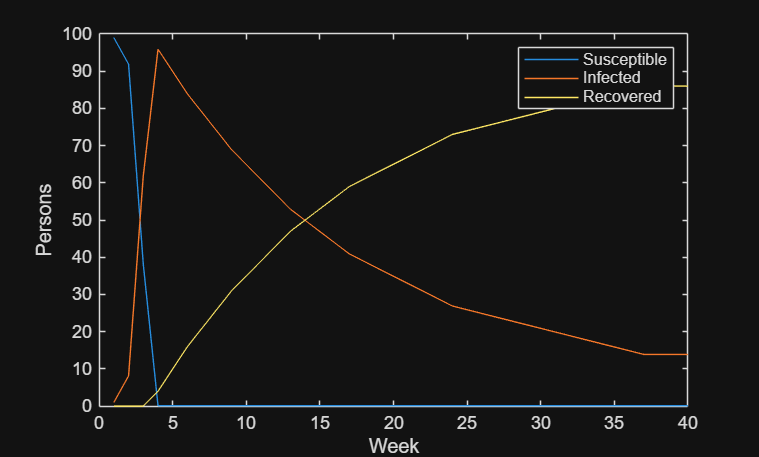

mi = 0.0800

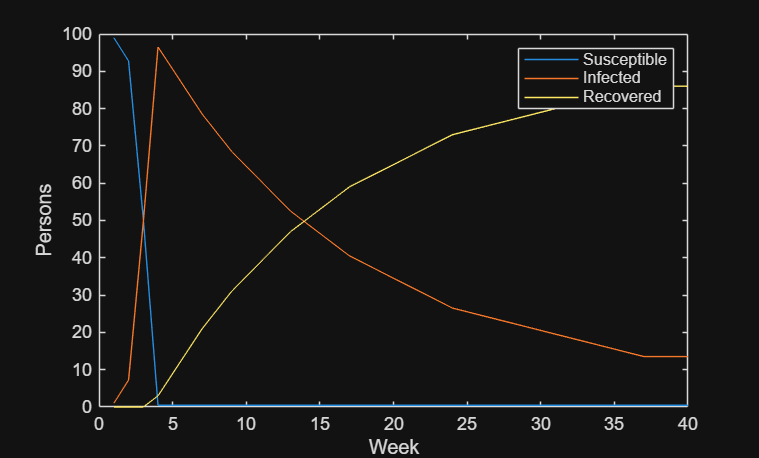

mi = 0.0700

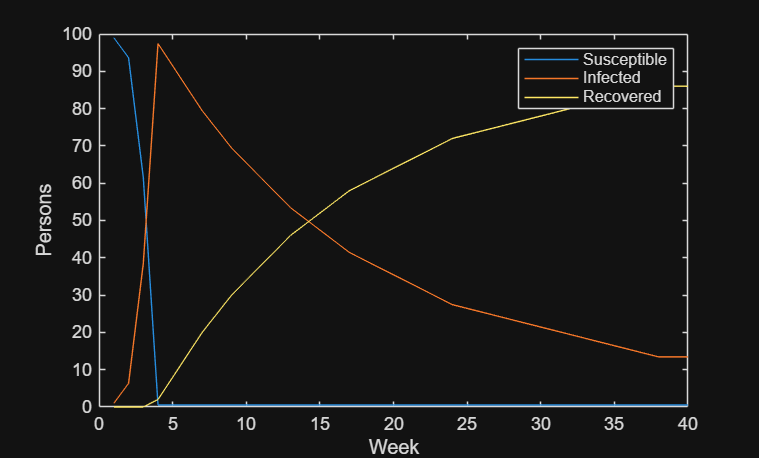

mi = 0.0600

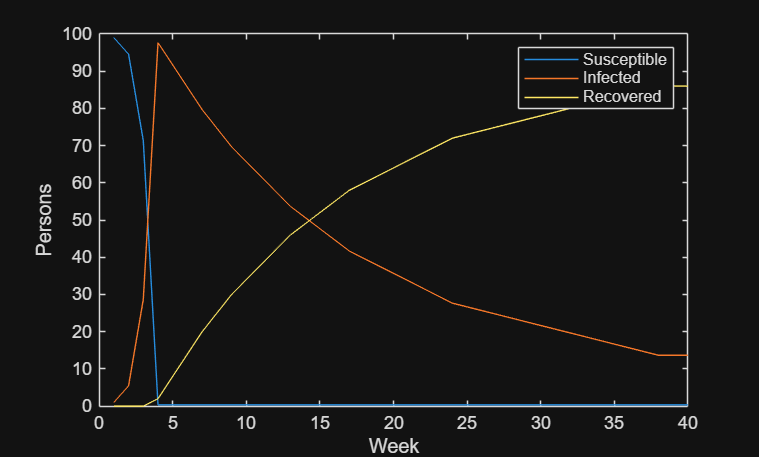

mi = 0.0500

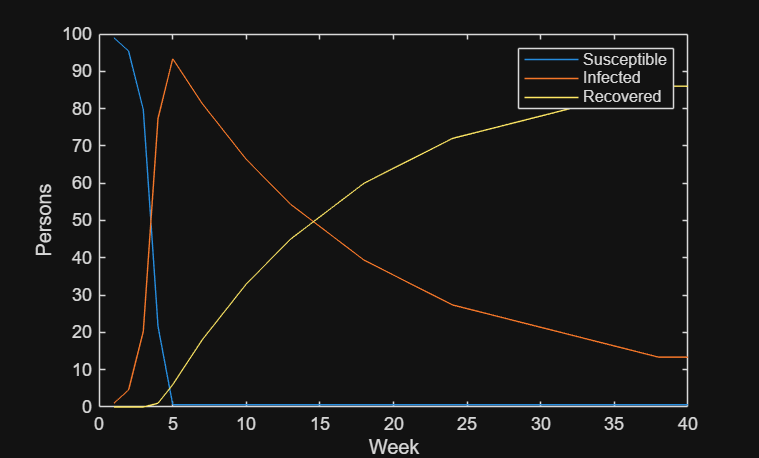

mi = 0.0400

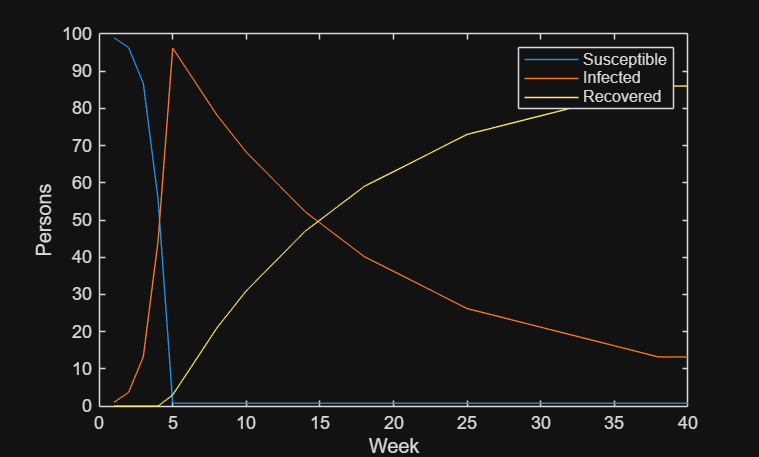

mi = 0.0300

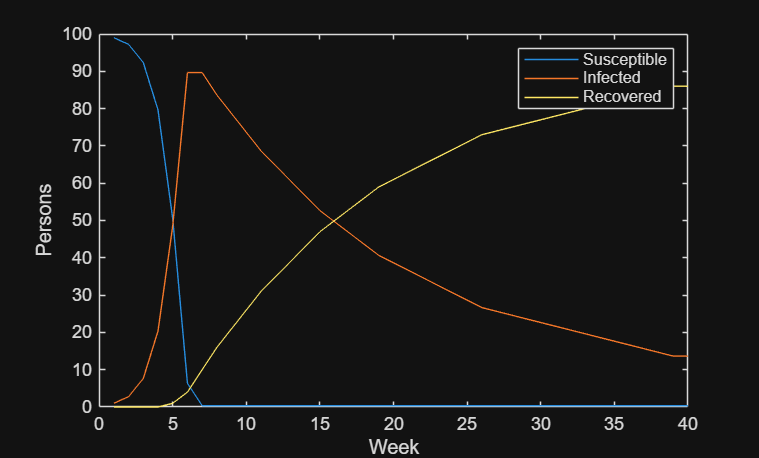

mi = 0.0200

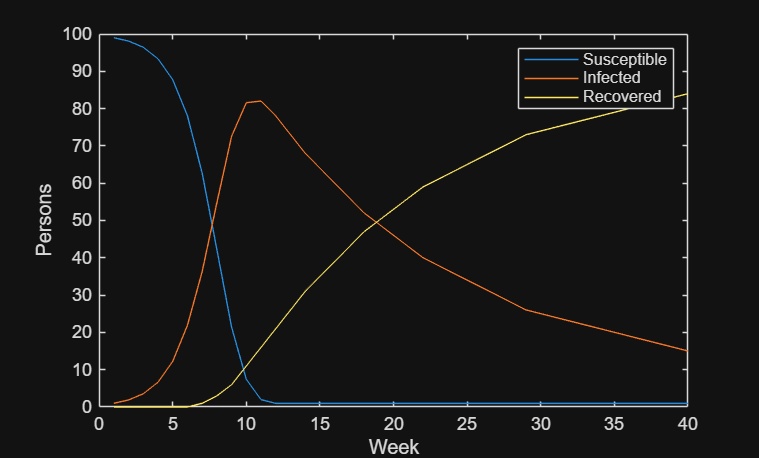

mi = 0.0100

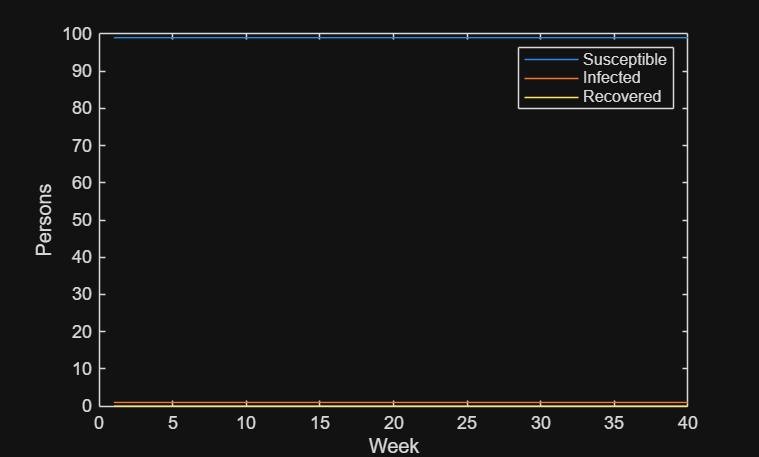

mi = 0

maxI = max(I);
idealI = maxI/2;

answer = 0;

for mi = 1:-0.01:0
    [Sx, Ix, Rx, Wx] = simulate_sir(S_1, I_1, R_1, mi, i, r, t_end);
    figure()
    plot(Wx, Sx, 'DisplayName', 'Susceptible'); hold on
    plot(Wx, Ix, 'DisplayName', 'Infected')
    plot(Wx, Rx, 'DisplayName', 'Recovered')
     
    xlabel("Week")
    ylabel("Persons")
    legend()
    mi
end


answer

answer = 0